clear, close all, clc

h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


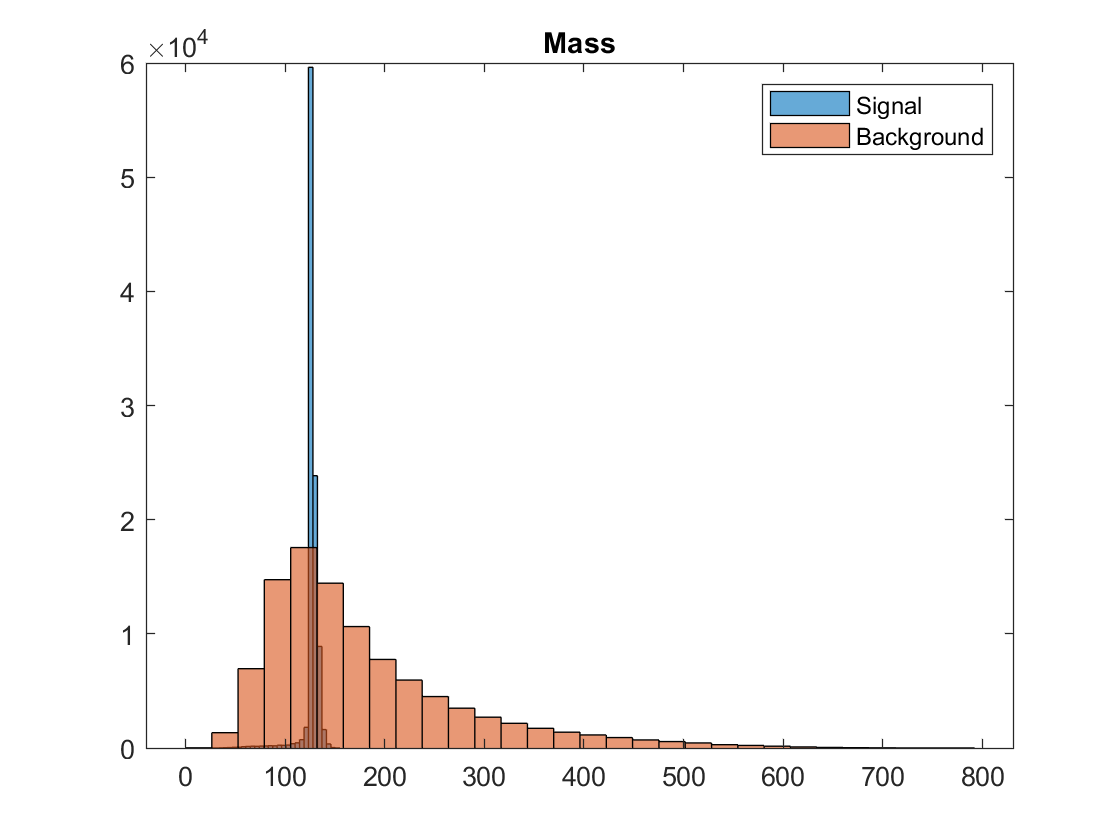


%h5disp("higgs_100000_pt_250_500.h5");
%h5disp("qcd_100000_pt_250_500.h5");

%sig_data = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
sig_data = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');

%bkgnd_data = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');
bkgnd_data = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

histogram(sig_data(4,:),30);
hold on
title('Mass')
histogram(bkgnd_data(4,:),30);
legend('Signal','Background')
hold off


step_hig = 0;
step_qcd = 0;

norm_mu = 20000*(100000-step_qcd)/100000;
norm_sig = 100*(100000-step_hig)/100000;
norm_comp = norm_mu+norm_sig;

Without doing any cuts we get a significance of 0.7112. Since our significance is so low the $\frac{N_{Higgs}}{\sqrt{N_{QCD}}}$ estimation is quite accurate at 0.7071.

Now we will do a mass cut between 200 and 100 and then normalize to 20000 qcd events and 100 higgs events. 


sig1 = poissinv(normcdf(5), norm_mu) % this is equivalent to Pythons poisson.ppf I believe

sig1 = 20711

sig2 = abs(norminv(1-poisscdf(norm_comp, norm_mu))) % this is equivalent to Pythons norm.ppf I believe

sig2 = 0.7112

sig3 = (norm_comp-norm_mu)/(sqrt(norm_mu))

sig3 = 0.7071


for i = 1:length(sig_data(4,:))
    if sig_data(4,i)>200 || sig_data(4,i)<100
         sig_data(:,i) = NaN*ones(1,14);
         step_hig = step_hig + 1;
    end
    if bkgnd_data(4,i)>200 || bkgnd_data(4,i)<100
         bkgnd_data(:,i) = NaN*ones(1,14);
         step_qcd = step_qcd + 1;
    end
end

norm_mu = 20000*(100000-step_qcd)/100000;
norm_sig = 100*(100000-step_hig)/100000;
norm_comp = norm_mu+norm_sig;

sig1 = poissinv(normcdf(5), norm_mu) % this is equivalent to Pythons poisson.ppf I believe

sig1 = 10684

sig2 = abs(norminv(1-poisscdf(norm_comp, norm_mu))) % this is equivalent to Pythons norm.ppf I believe

sig2 = 0.9746

sig3 = (norm_comp-norm_mu)/(sqrt(norm_mu))

sig3 = 0.9721

The above mass cut between 200 and 100 results in a significance of 0.9746. The estimated significance is 0.9720, reasonably close to our measured value.


for i = 1:length(sig_data(4,:))
    if sig_data(4,i)>130 || sig_data(4,i)<124
         sig_data(:,i) = NaN*ones(1,14);
         step_hig = step_hig + 1;
    end
    if bkgnd_data(4,i)>130 || bkgnd_data(4,i)<124
         bkgnd_data(:,i) = NaN*ones(1,14);
         step_qcd = step_qcd + 1;
    end
end

norm_mu = 20000*(100000-step_qcd)/100000;
norm_sig = 100*(100000-step_hig)/100000;
norm_comp = norm_mu+norm_sig;

sig1 = poissinv(normcdf(5), norm_mu) % this is equivalent to Pythons poisson.ppf I believe

sig1 = 904

sig2 = abs(norminv(1-poisscdf(norm_comp, norm_mu))) % this is equivalent to Pythons norm.ppf I believe

sig2 = 2.6478

sig3 = (norm_comp-norm_mu)/(sqrt(norm_mu))

sig3 = 2.6725

Using a mass cut of 120 to 130 I was able to achieve a significance of 2.6478 which is not above the 5 sigma so we need to further optimize our event selections by including additional features to cut. We will now make stacked histogram for the rest of the features to use for further cuts.

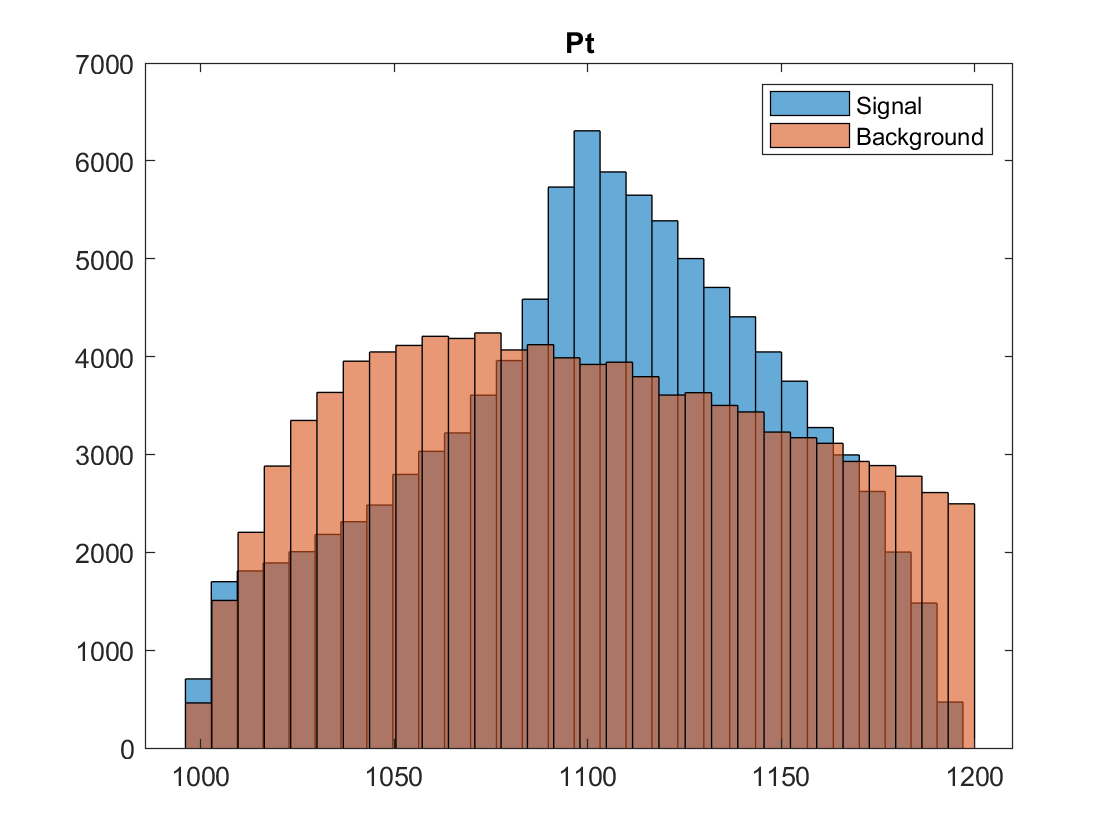

sig2_data = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');

bkgnd2_data = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

histogram(sig2_data(1,:),30);
hold on
title('Pt')
histogram(bkgnd2_data(1,:),30);
legend('Signal','Background')
hold off

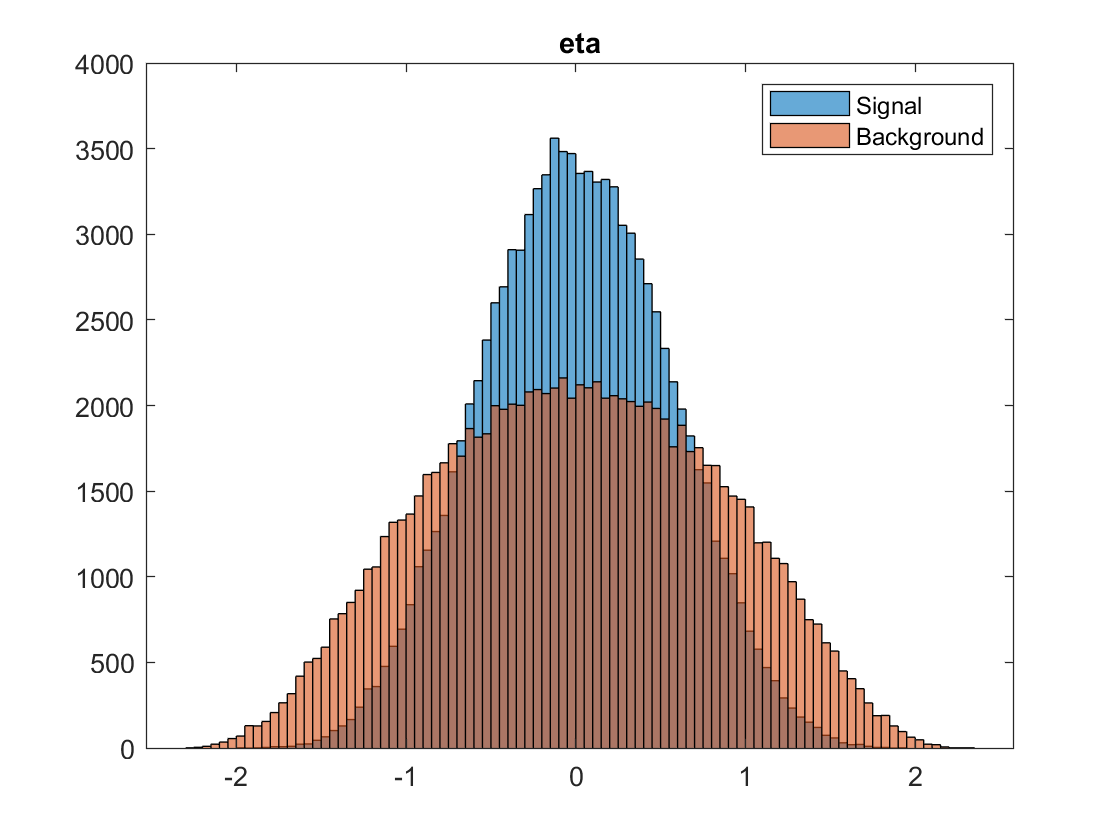


histogram(sig2_data(2,:))
title('eta')
hold on
histogram(bkgnd2_data(2,:))
hold off
legend('Signal','Background')

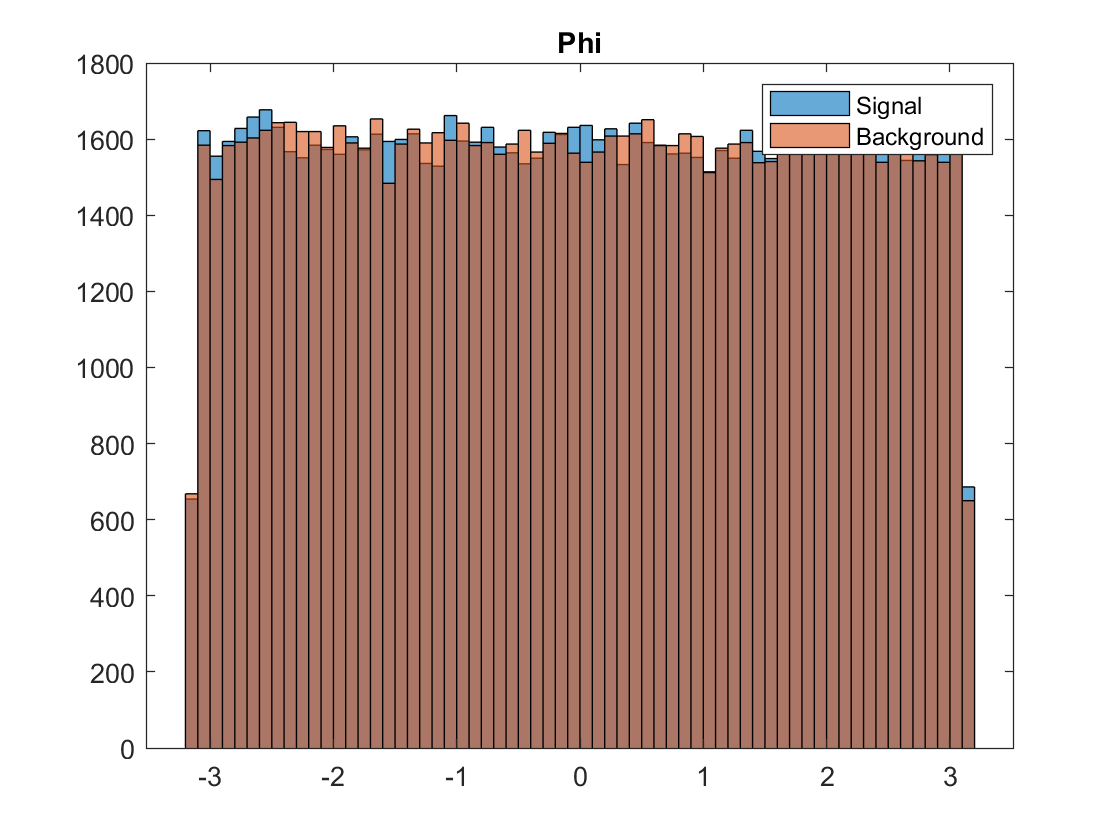


histogram(sig2_data(3,:))
title('Phi')
hold on
histogram(bkgnd2_data(3,:))
hold off
legend('Signal','Background')

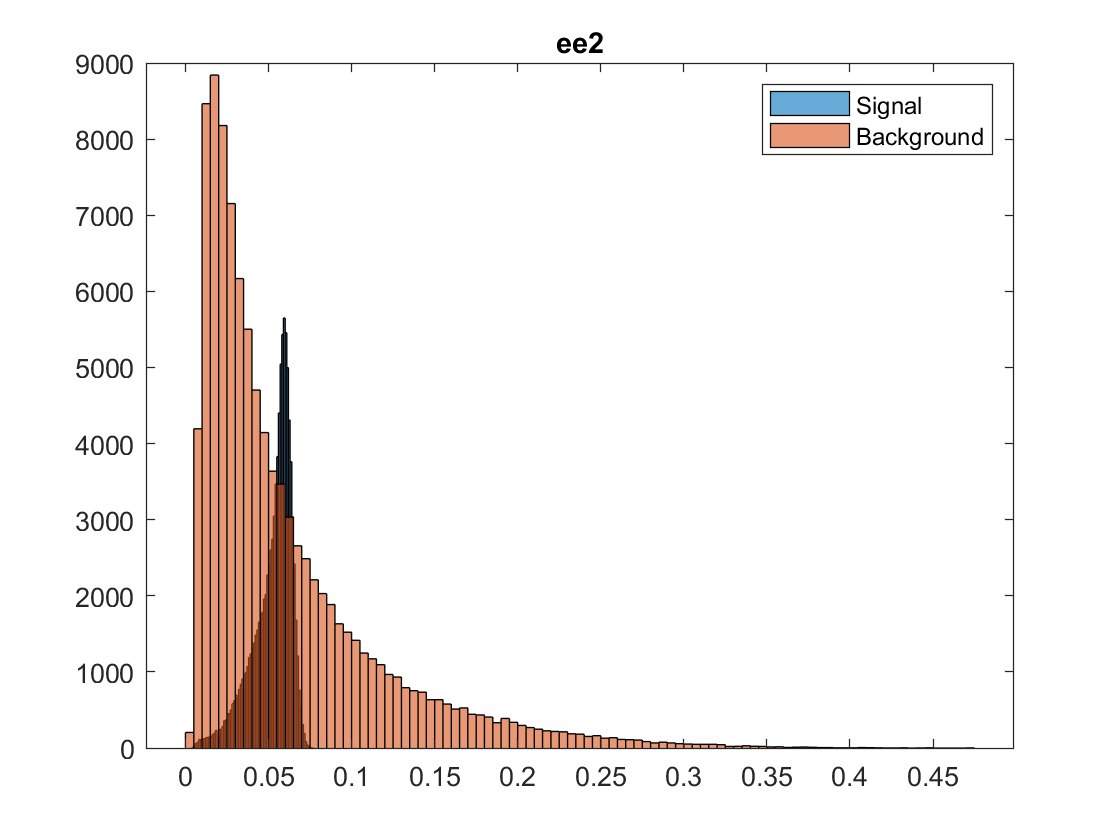



histogram(sig2_data(5,:))
title('ee2')
hold on
histogram(bkgnd2_data(5,:))
legend('Signal','Background')
hold off

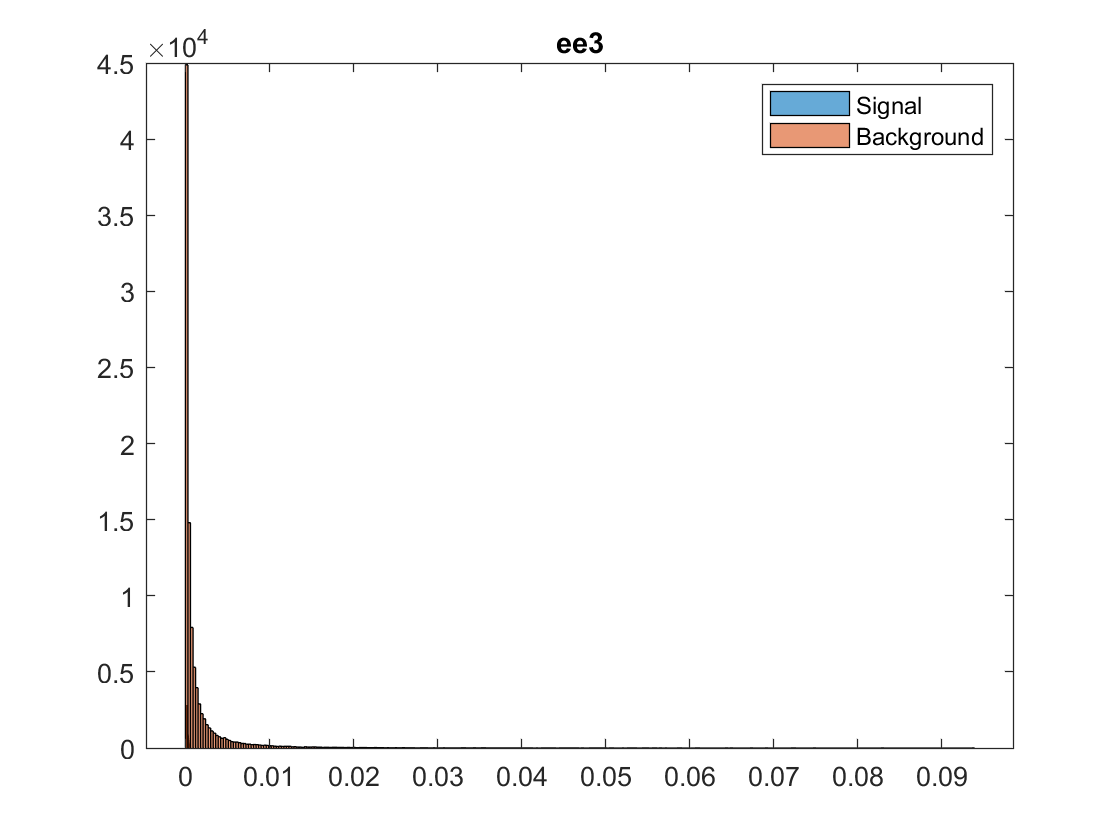


histogram(sig2_data(6,:))
title('ee3')
hold on
histogram(bkgnd2_data(6,:))
hold off
legend('Signal','Background')

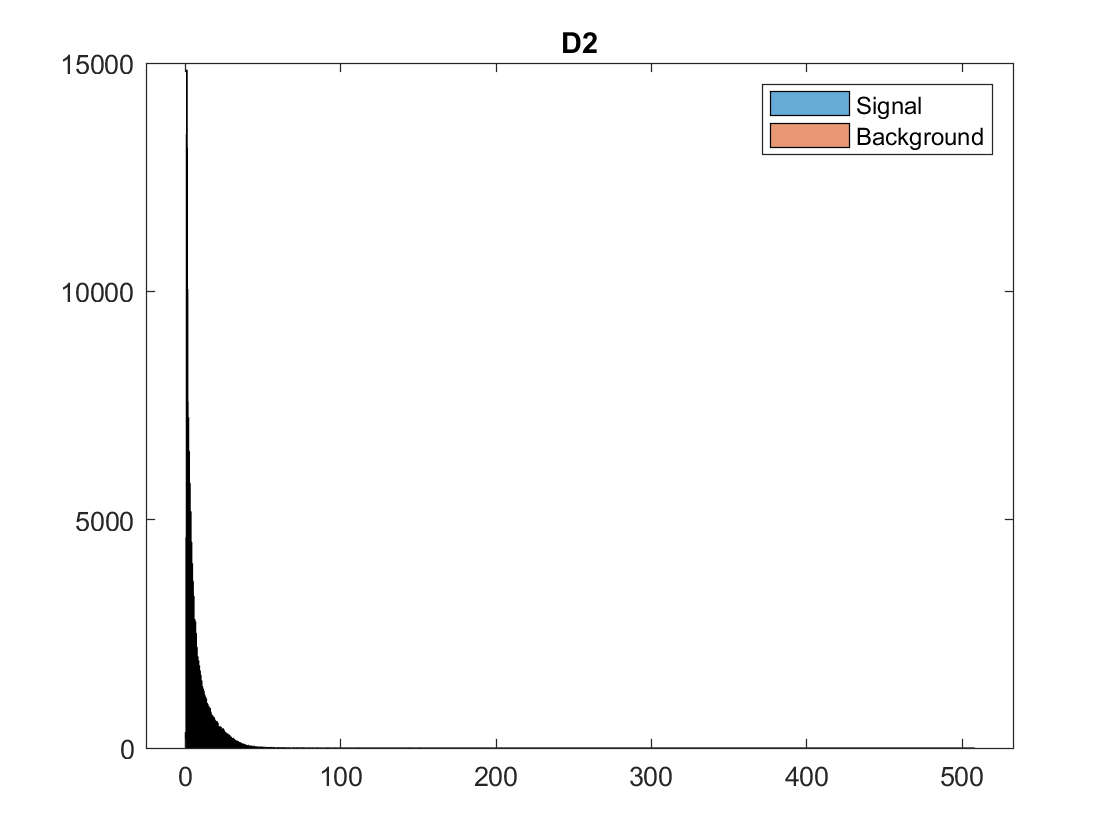


histogram(sig2_data(7,:))
title('D2')
hold on
histogram(bkgnd2_data(7,:))
hold off
legend('Signal','Background')

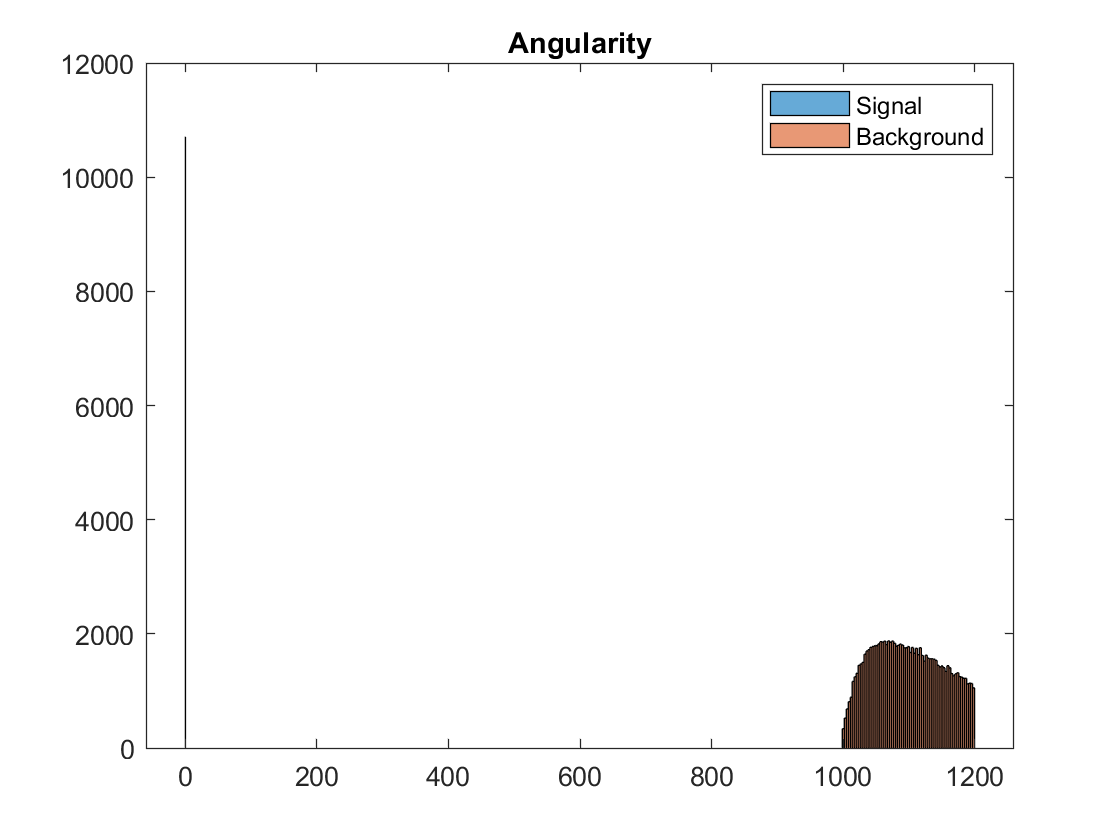


histogram(sig2_data(8,:))
title('Angularity')
hold on
histogram(bkgnd2_data(1,:))
hold off
legend('Signal','Background')

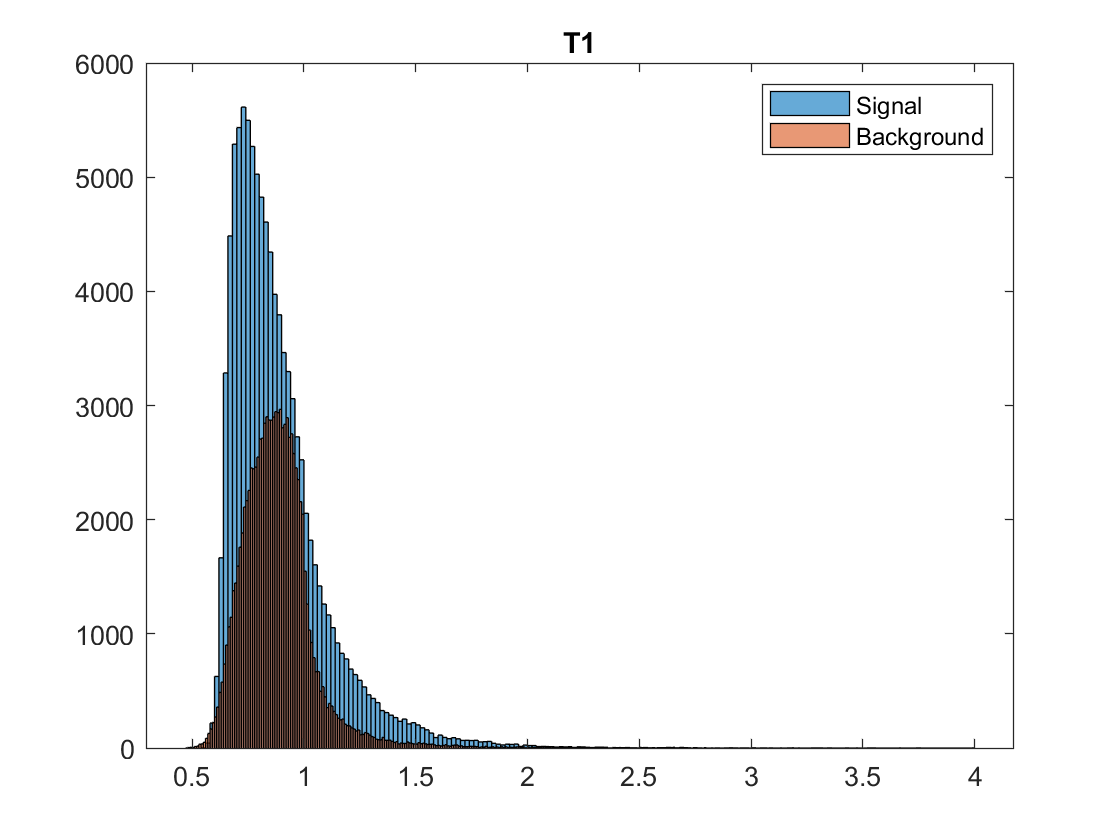



histogram(sig2_data(9,:))
title('T1')
hold on
histogram(bkgnd2_data(9,:))
hold off
legend('Signal','Background')

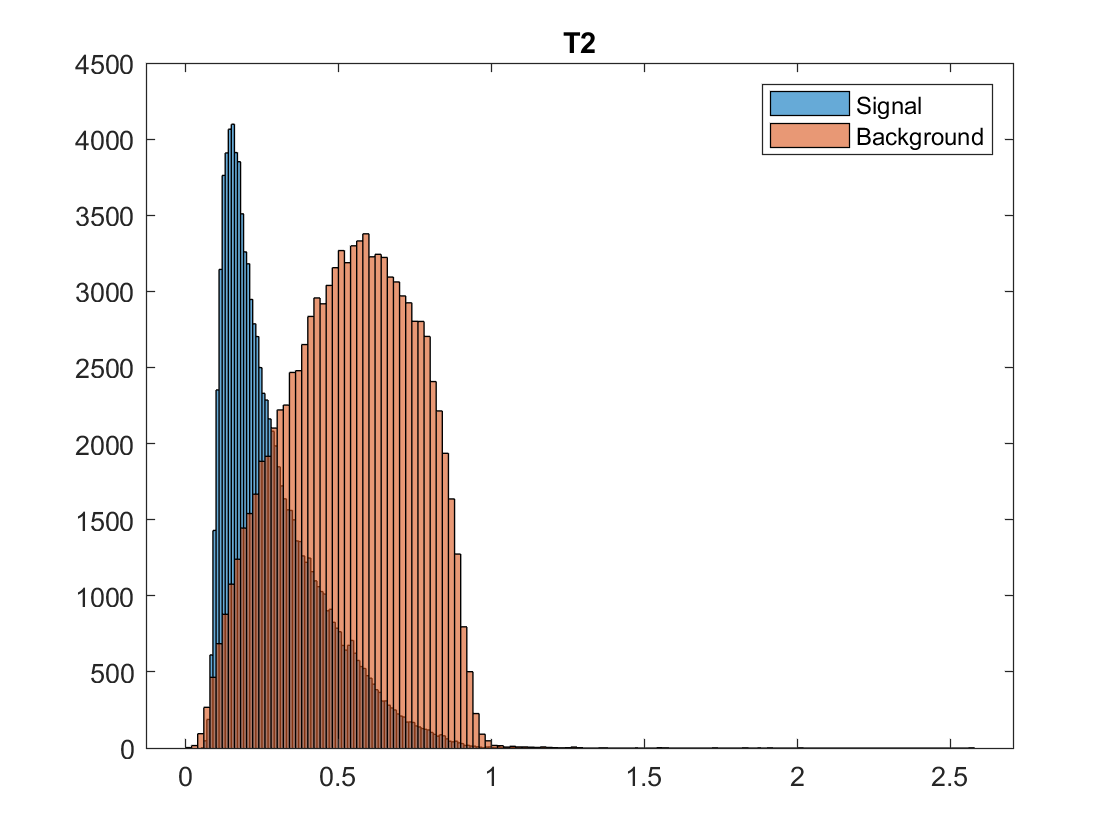



histogram(sig2_data(10,:))
title('T2')
hold on
histogram(bkgnd2_data(10,:))
legend('Signal','Background')
hold off

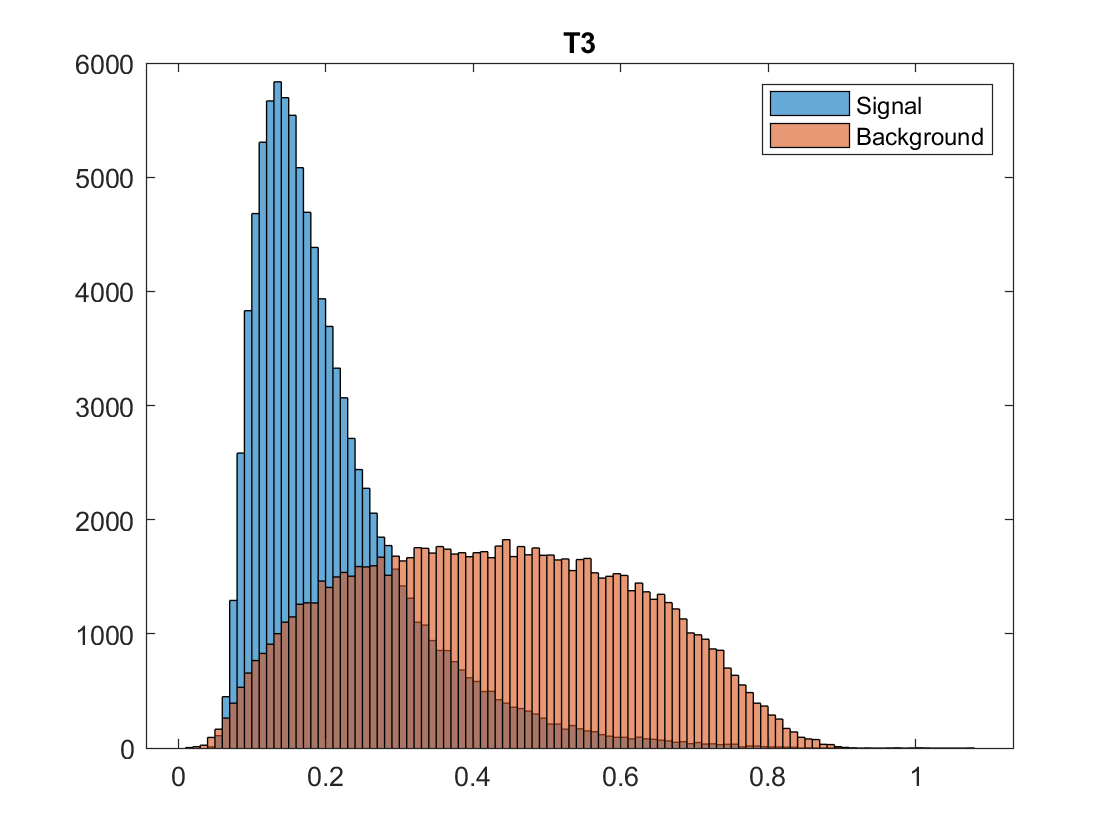


histogram(sig2_data(11,:))
title('T3')
hold on
histogram(bkgnd2_data(11,:))
legend('Signal','Background')
hold off

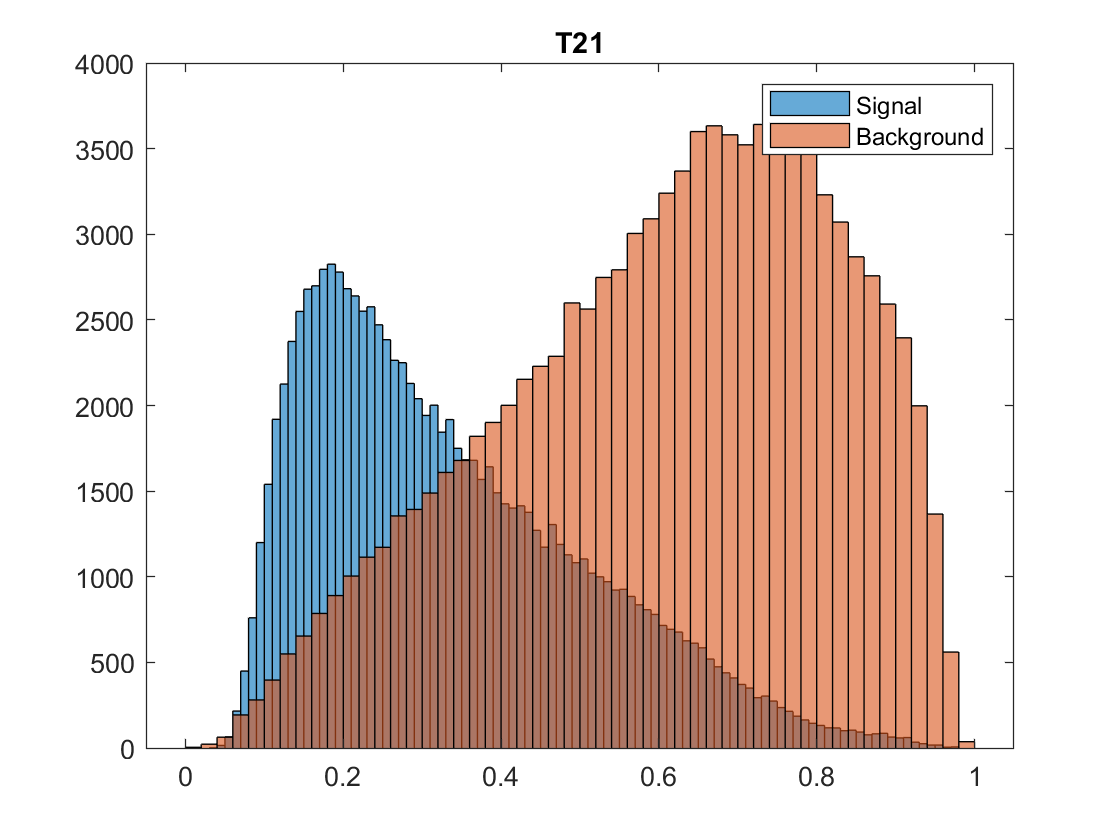


histogram(sig2_data(12,:))
title('T21')
hold on
histogram(bkgnd2_data(12,:))
legend('Signal','Background')
hold off

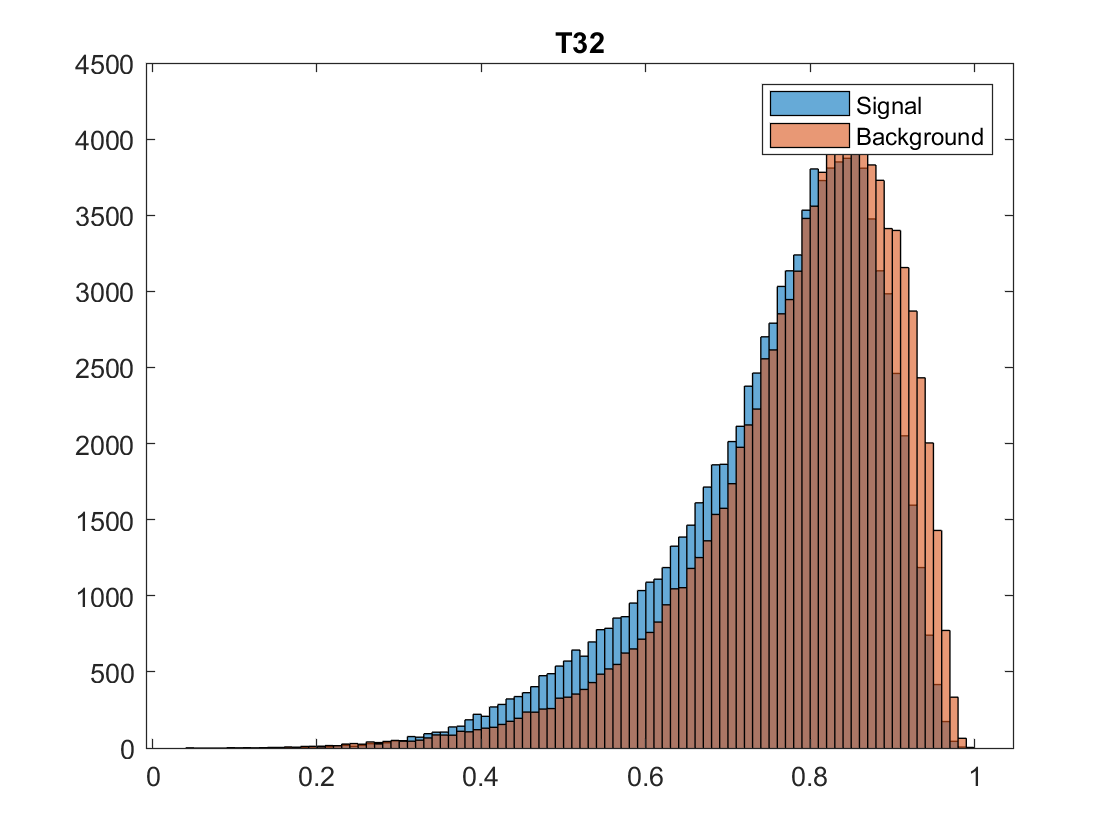



histogram(sig2_data(13,:))
title('T32')
hold on
histogram(bkgnd2_data(13,:))
legend('Signal','Background')
hold off

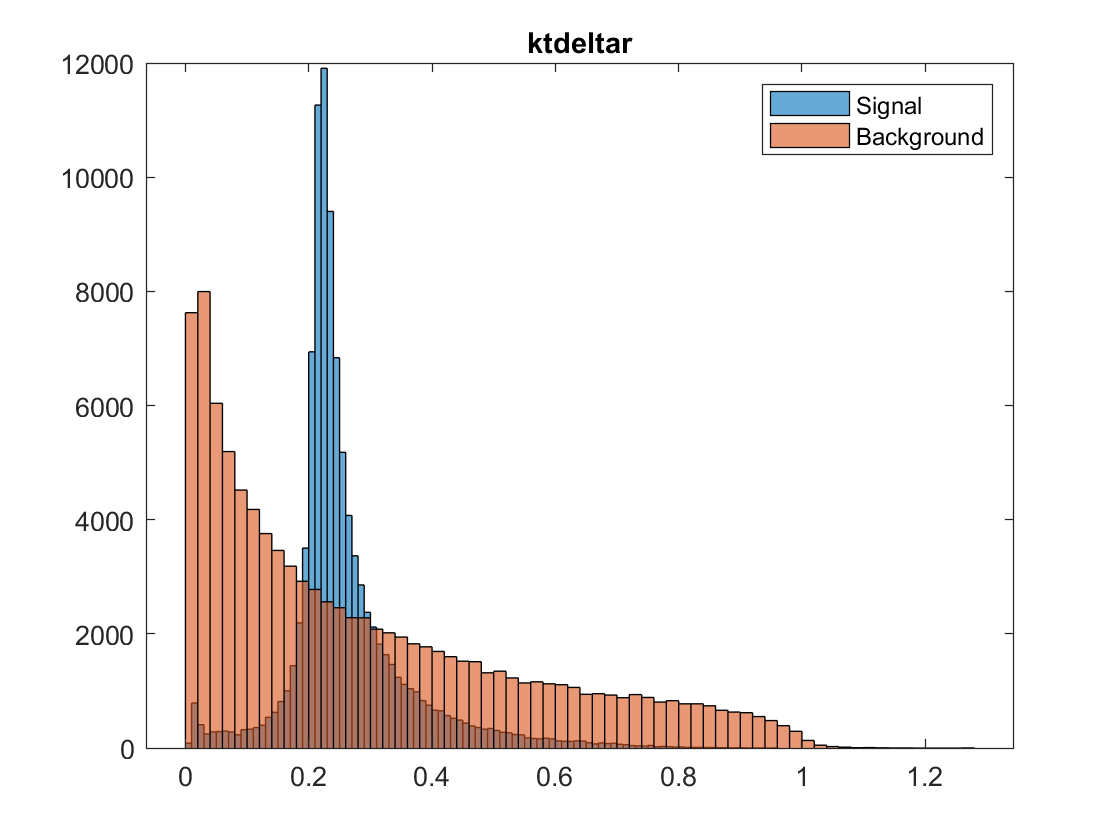


histogram(sig2_data(14,:))
title('ktdeltar')
hold on
histogram(bkgnd2_data(14,:))
legend('Signal','Background')
hold off

Above is set A without any mass cuts.

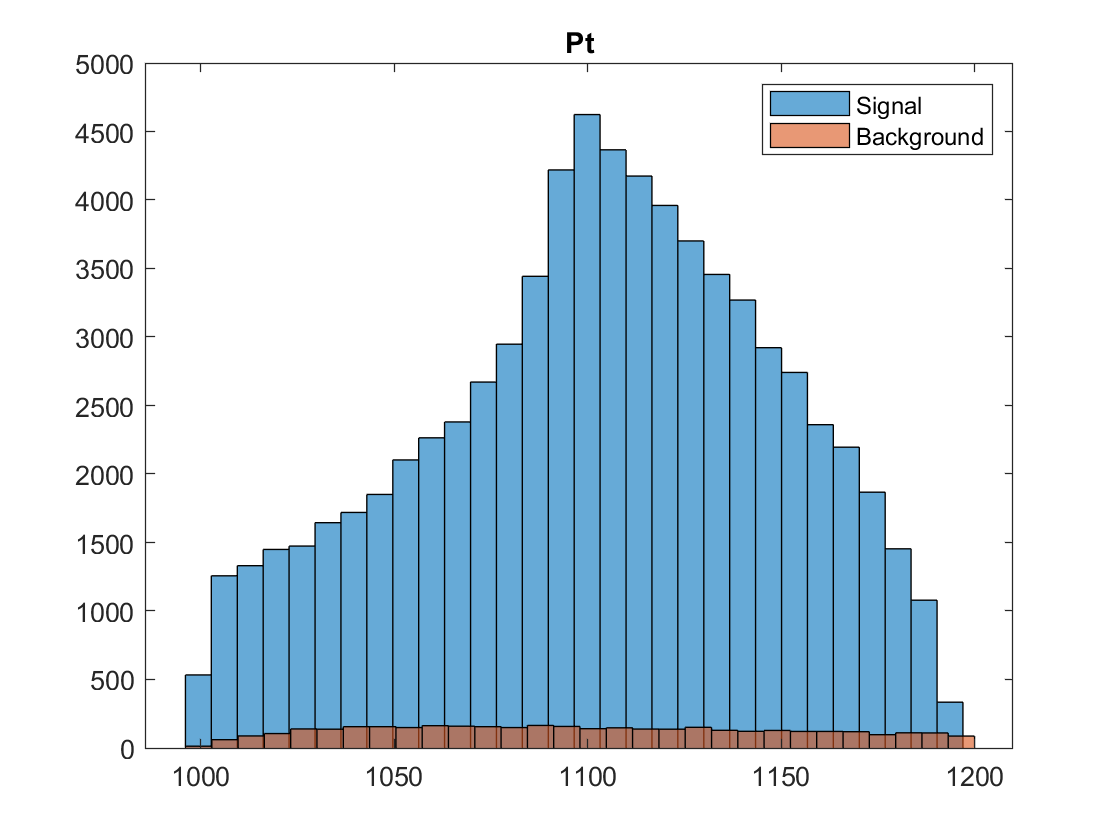

histogram(sig_data(1,:),30);
hold on
title('Pt')
histogram(bkgnd_data(1,:),30);
legend('Signal','Background')
hold off

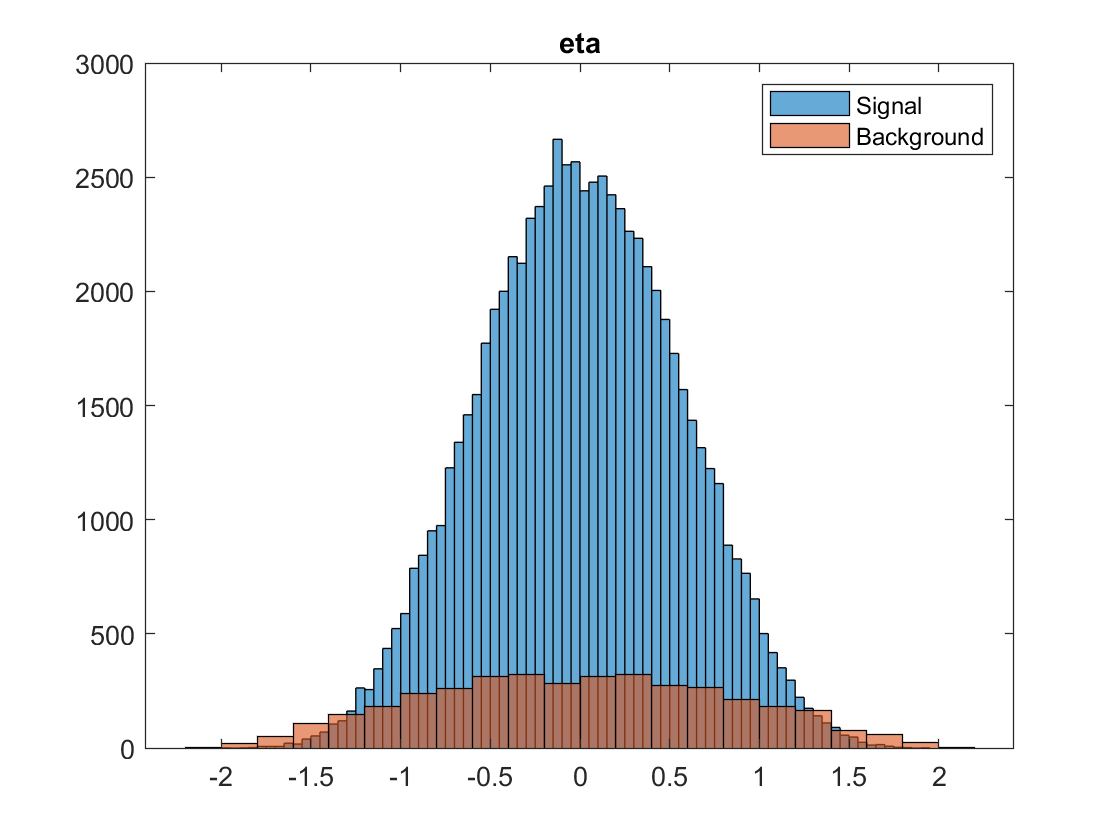



histogram(sig_data(2,:))
title('eta')
hold on
histogram(bkgnd_data(2,:))
hold off
legend('Signal','Background') 

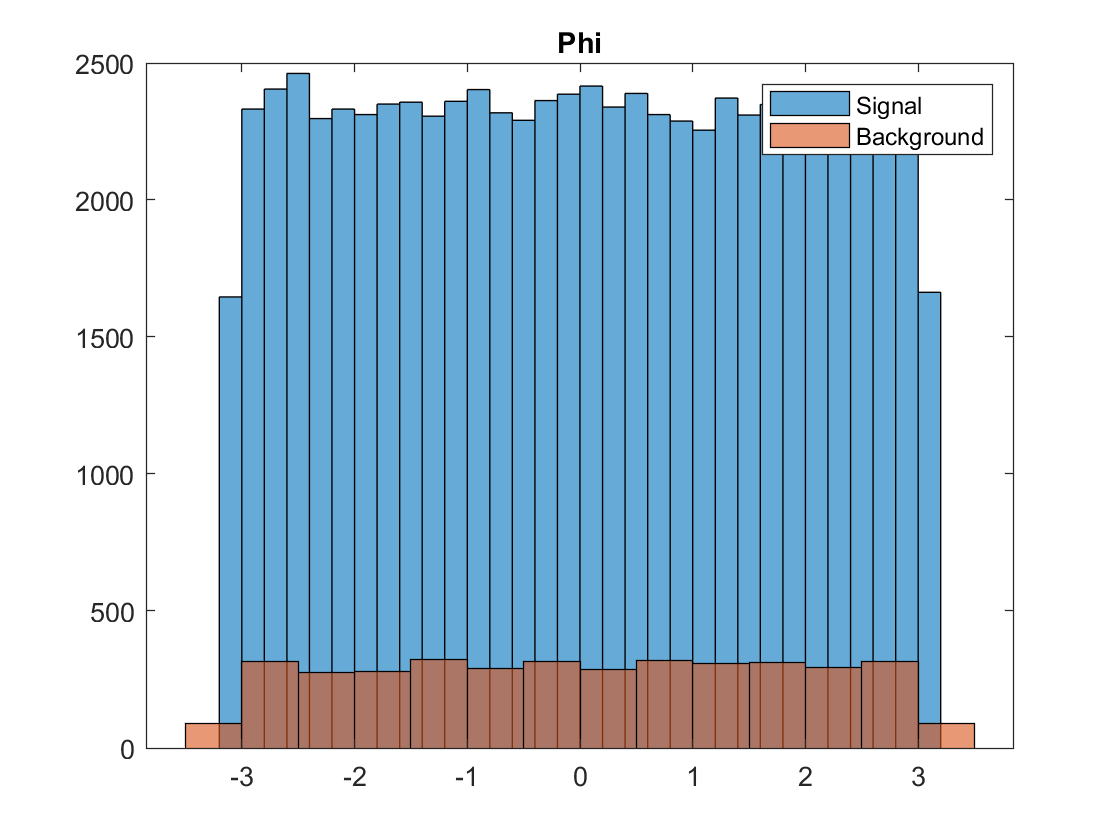


histogram(sig_data(3,:))
title('Phi')
hold on
histogram(bkgnd_data(3,:))
hold off
legend('Signal','Background')

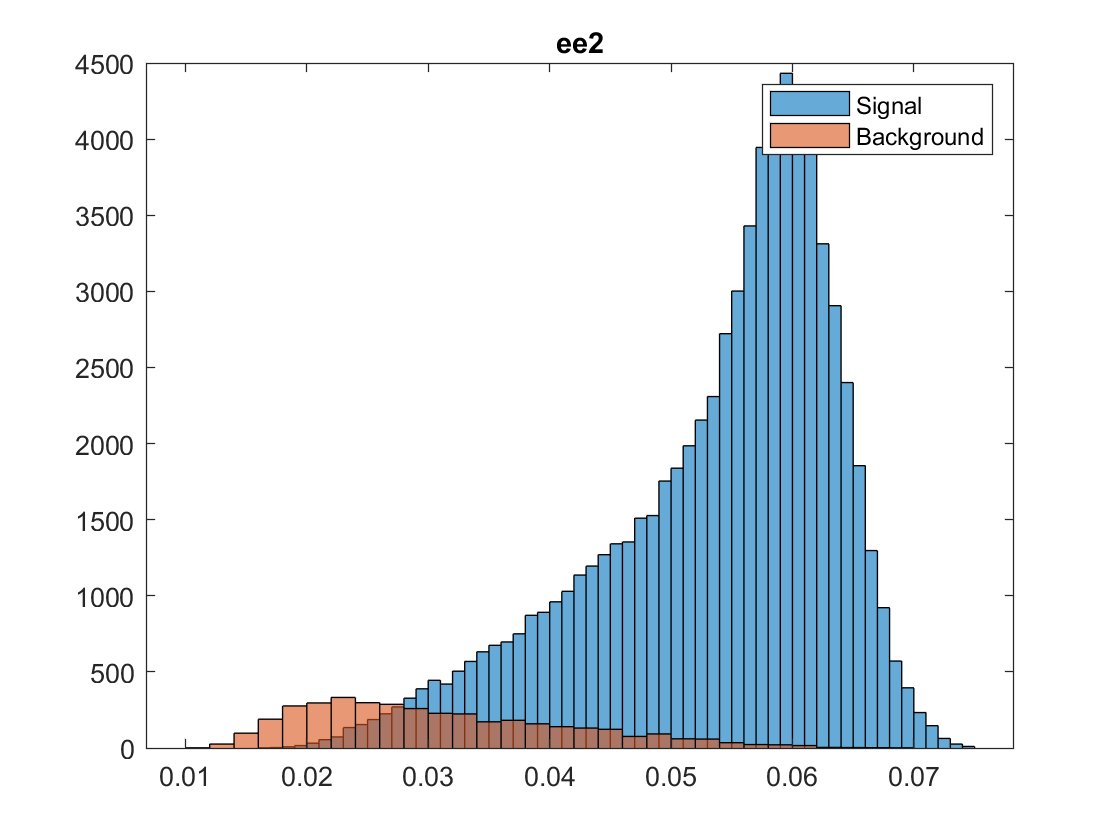



histogram(sig_data(5,:))
title('ee2')
hold on
histogram(bkgnd_data(5,:))
legend('Signal','Background')
hold off

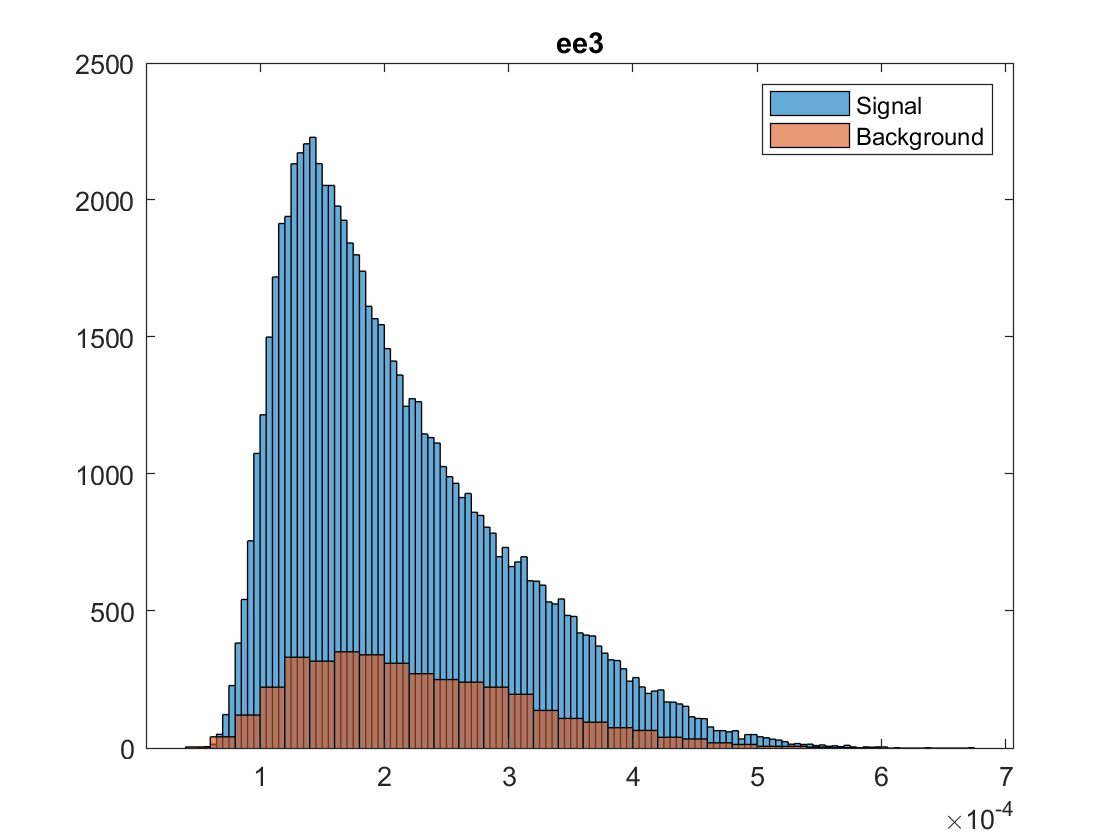


histogram(sig_data(6,:))
title('ee3')
hold on
histogram(bkgnd_data(6,:))
hold off
legend('Signal','Background')

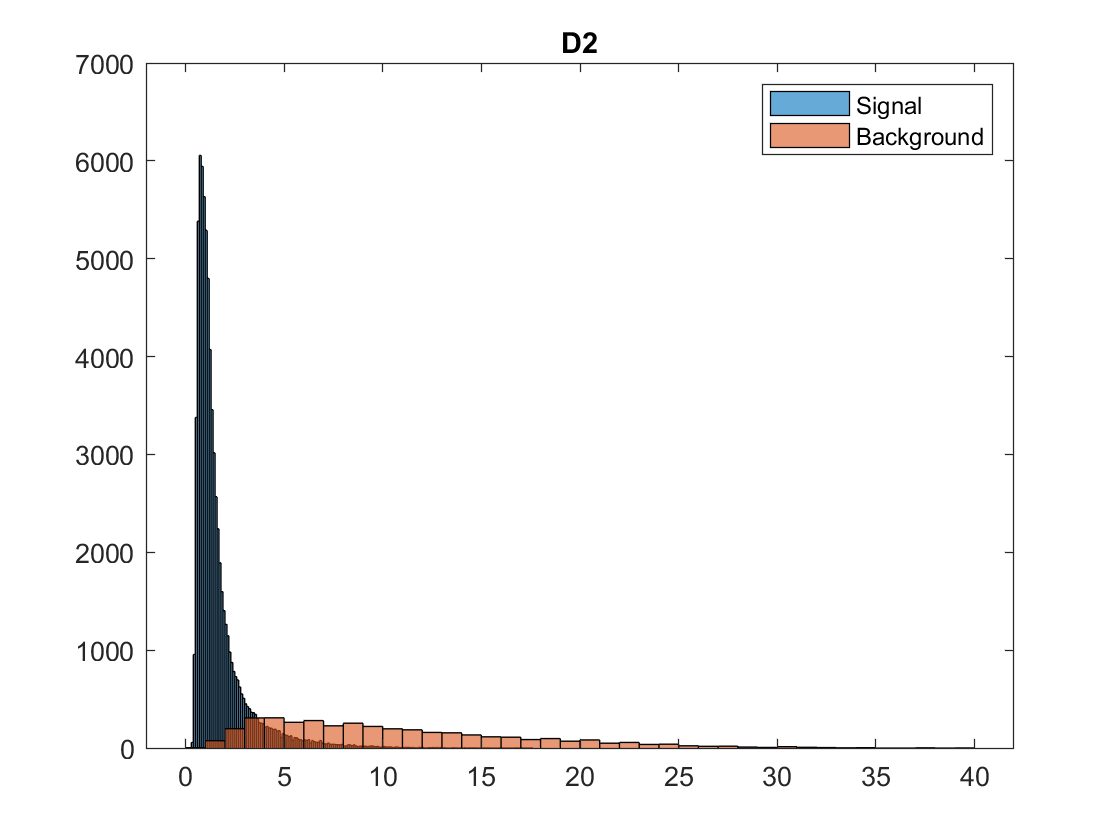


histogram(sig_data(7,:))
title('D2')
hold on
histogram(bkgnd_data(7,:))
hold off
legend('Signal','Background')

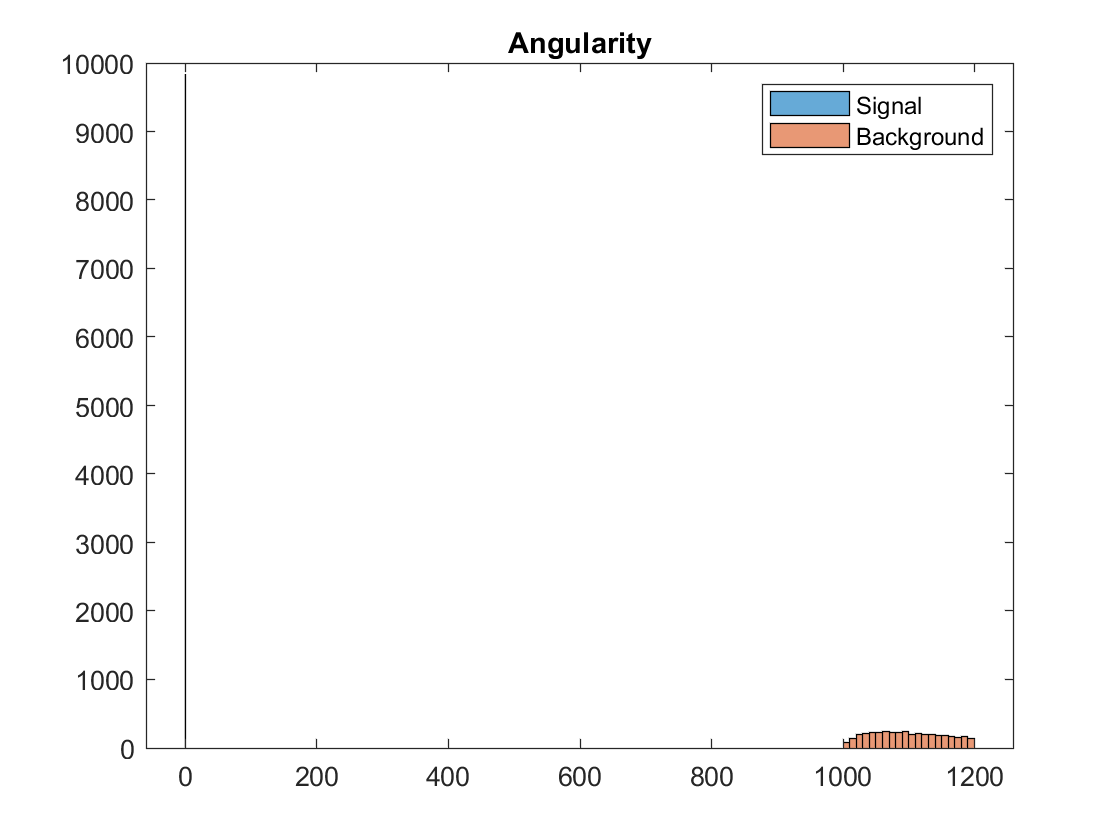


histogram(sig_data(8,:))
title('Angularity')
hold on
histogram(bkgnd_data(1,:))
hold off
legend('Signal','Background')

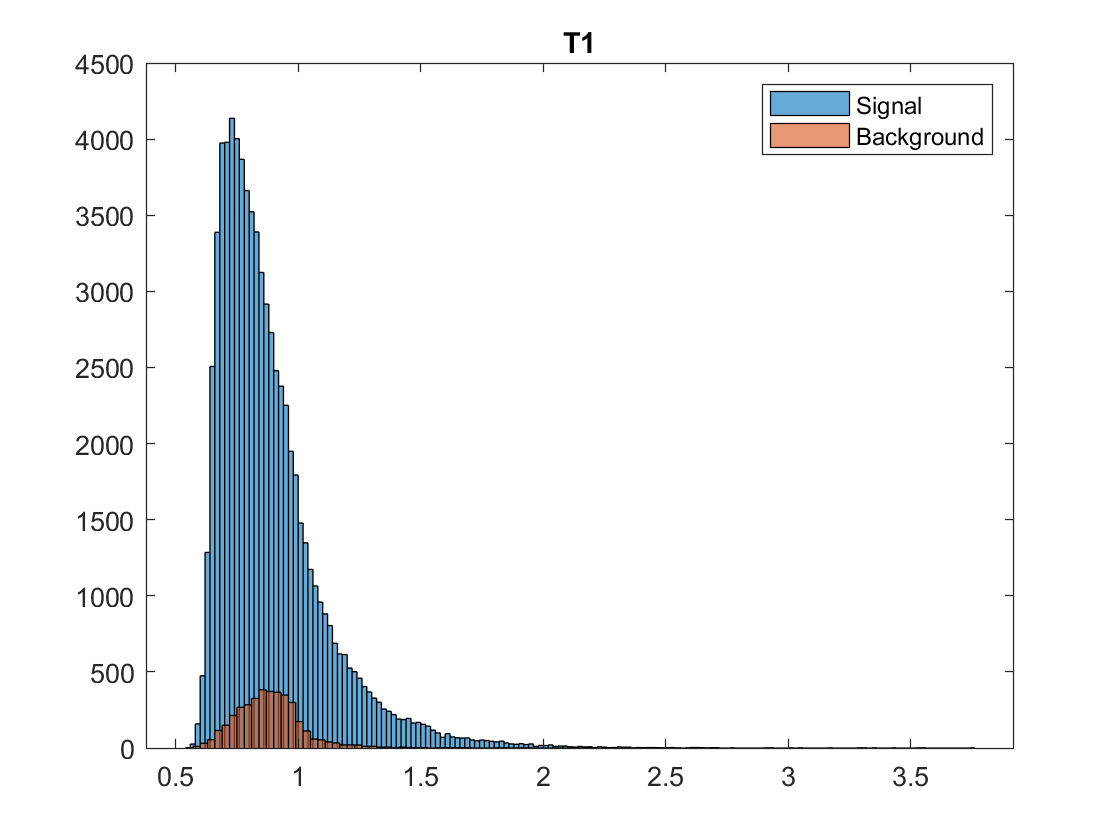


histogram(sig_data(9,:))
title('T1')
hold on
histogram(bkgnd_data(9,:))
hold off
legend('Signal','Background')

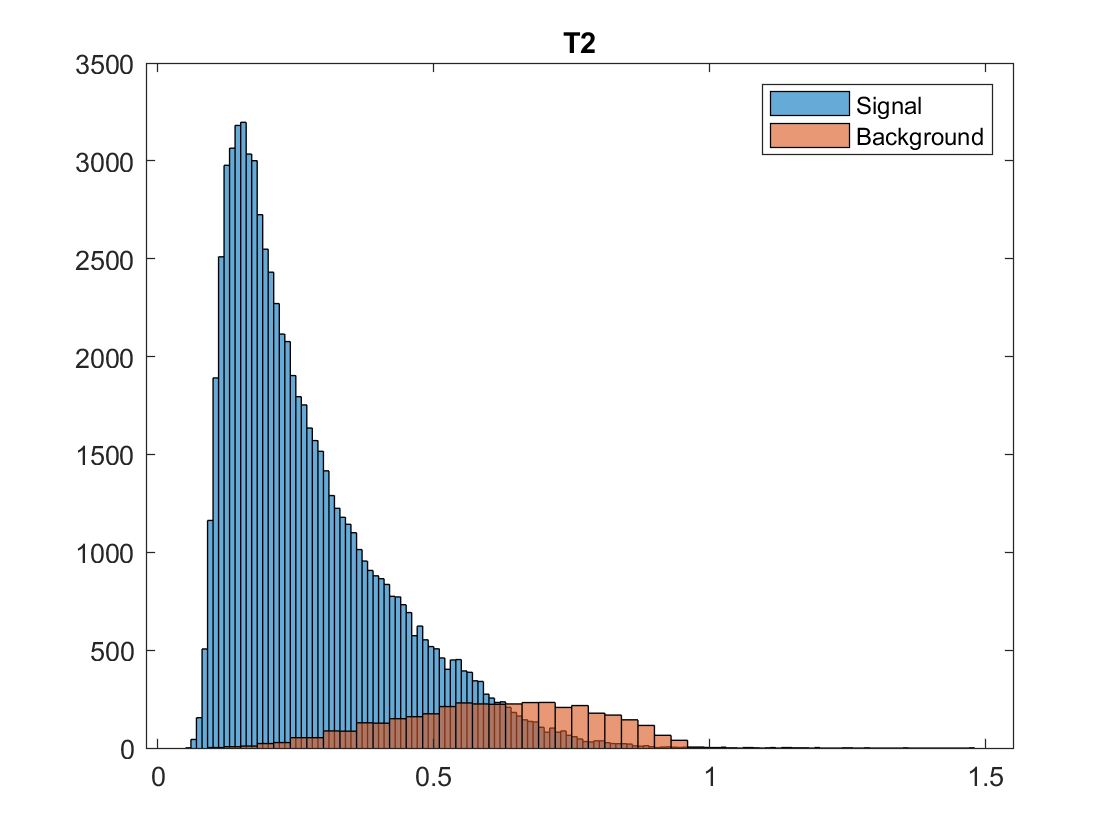


histogram(sig_data(10,:))
title('T2')
hold on
histogram(bkgnd_data(10,:))
legend('Signal','Background')
hold off

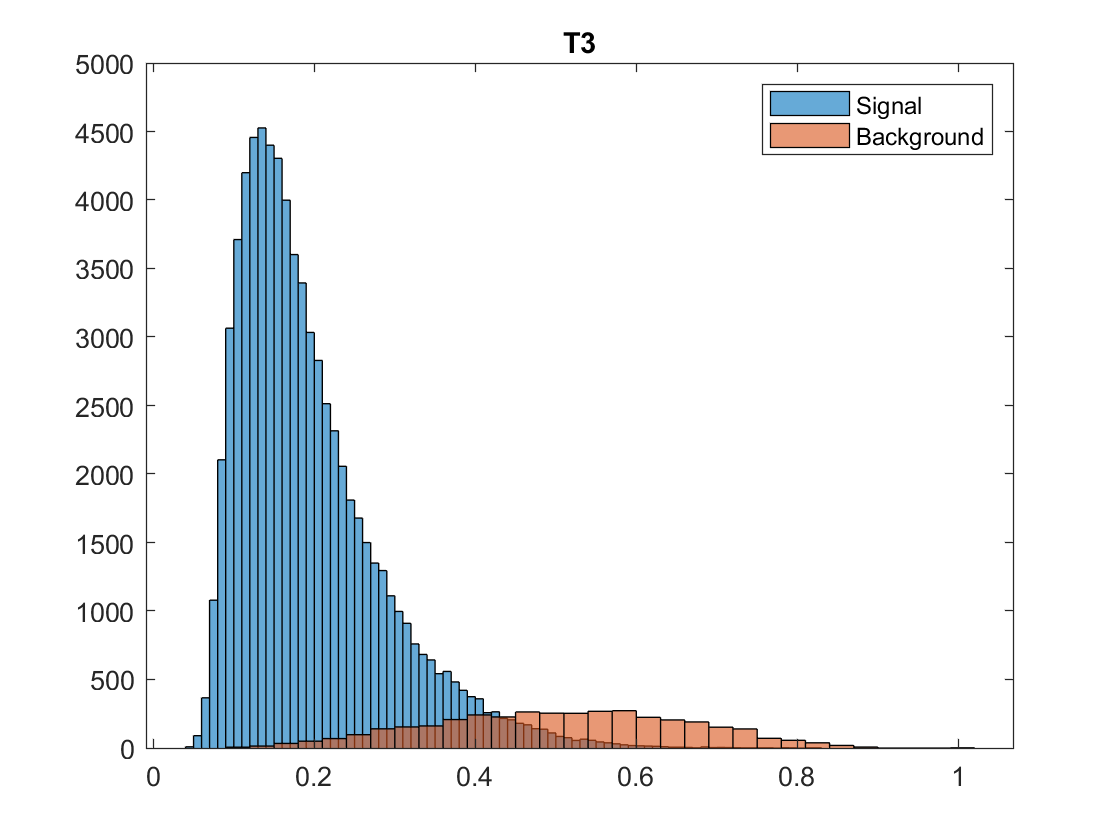


histogram(sig_data(11,:))
title('T3')
hold on
histogram(bkgnd_data(11,:))
legend('Signal','Background')
hold off

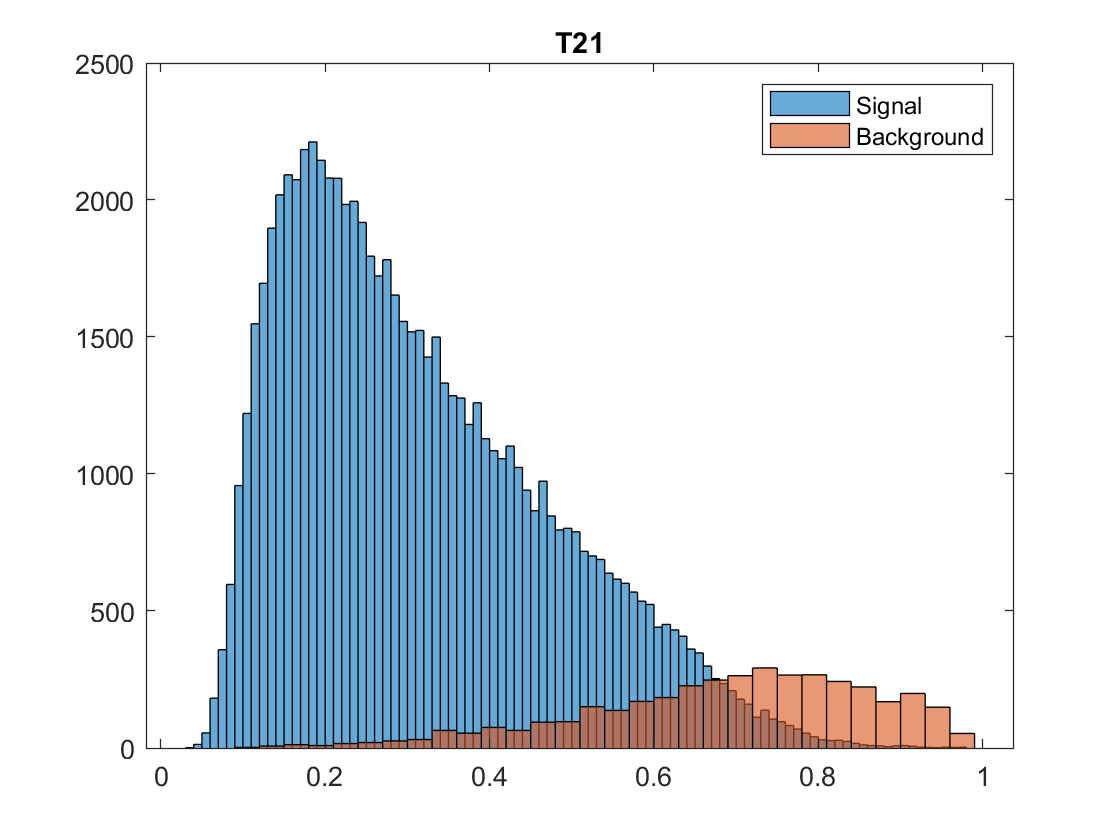


histogram(sig_data(12,:))
title('T21')
hold on
histogram(bkgnd_data(12,:))
legend('Signal','Background')
hold off

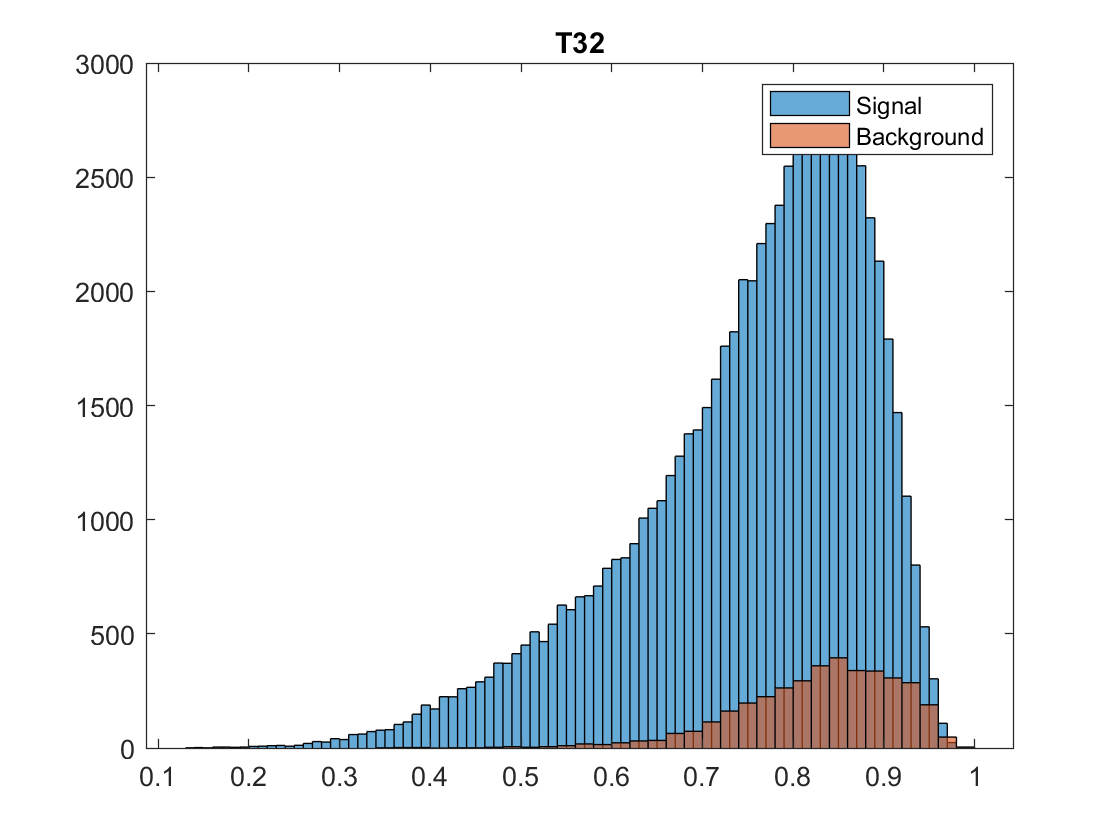


histogram(sig_data(13,:))
title('T32')
hold on
histogram(bkgnd_data(13,:))
legend('Signal','Background')
hold off

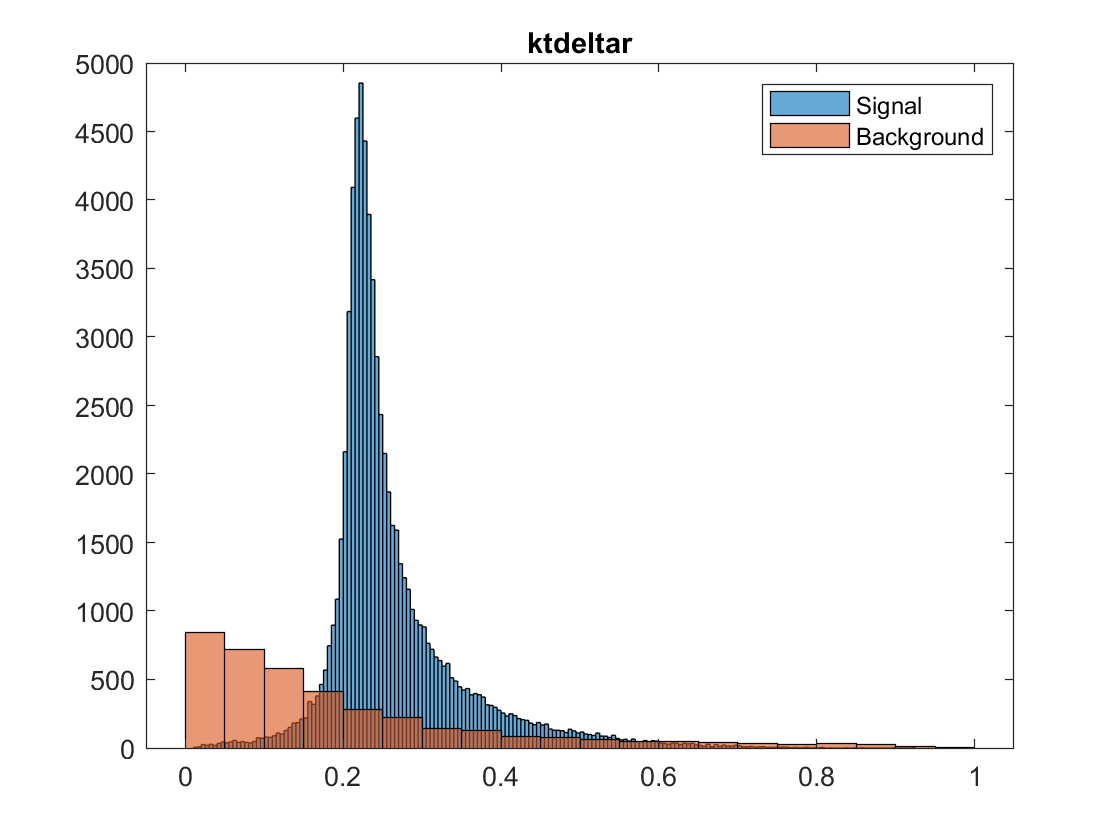


histogram(sig_data(14,:))
title('ktdeltar')
hold on
histogram(bkgnd_data(14,:))
legend('Signal','Background')
hold off

Above is set B with mass cuts. 

for i = 1:length(sig_data(10,:))
    if sig_data(10,i)>0.6 || sig_data(10,i)<0
         sig_data(:,i) = NaN*ones(1,14);
         step_hig = step_hig + 1;
    end
    if bkgnd_data(10,i)>0.6 || bkgnd_data(10,i)<0
         bkgnd_data(:,i) = NaN*ones(1,14);
         step_qcd = step_qcd + 1;
    end
end

norm_mu = 20000*(100000-step_qcd)/100000;
norm_sig = 100*(100000-step_hig)/100000;
norm_comp = norm_mu+norm_sig;

sig1 = poissinv(normcdf(5), norm_mu) % this is equivalent to Pythons poisson.ppf I believe

sig1 = 449

sig2 = abs(norminv(1-poisscdf(norm_comp, norm_mu))) % this is equivalent to Pythons norm.ppf I believe

sig2 = 3.6833

sig3 = (norm_comp-norm_mu)/(sqrt(norm_mu))

sig3 = 3.7943

Using a T2 cut of 0 to 0.6 I was able to achieve a significance of 3.6833 which is not into the 5 sigma value so we need to include additional features if we want to achieve a 5 sigma. Now we will try a ktdeltaR cut from 0.17 to 1 and T3 cut from 0 to 0.4.



for i = 1:length(sig_data(14,:))
    if sig_data(14,i)>1 || sig_data(14,i)<0.17
         sig_data(:,i) = NaN*ones(1,14);
         step_hig = step_hig + 1;
    end
    if bkgnd_data(14,i)>1 || bkgnd_data(14,i)<0.17
         bkgnd_data(:,i) = NaN*ones(1,14);
         step_qcd = step_qcd + 1;
    end
end

norm_mu = 20000*(100000-step_qcd)/100000;
norm_sig = 100*(100000-step_hig)/100000;
norm_comp = norm_mu+norm_sig;

sig1 = poissinv(normcdf(5), norm_mu) % this is equivalent to Pythons poisson.ppf I believe

sig1 = 271

sig2 = abs(norminv(1-poisscdf(norm_comp, norm_mu))) % this is equivalent to Pythons norm.ppf I believe

sig2 = 4.6734

sig3 = (norm_comp-norm_mu)/(sqrt(norm_mu))

sig3 = 4.9269


% histogram(sig_data(11,:))
% hold on
% histogram(bkgnd_data(11,:))
% hold off

for i = 1:length(sig_data(11,:))
    if sig_data(11,i)>0.4 || sig_data(11,i)<0
         sig_data(:,i) = NaN*ones(1,14);
         step_hig = step_hig + 1;
    end
    if bkgnd_data(11,i)>0.4 || bkgnd_data(11,i)<0
         bkgnd_data(:,i) = NaN*ones(1,14);
         step_qcd = step_qcd + 1;
    end
end

norm_mu = 20000*(100000-step_qcd)/100000;
norm_sig = 100*(100000-step_hig)/100000;
norm_sig_lab8 = 2*(100000-step_hig)/100000;
norm_comp = norm_mu+norm_sig;

sig1 = poissinv(normcdf(5), norm_mu) % this is equivalent to Pythons poisson.ppf I believe

sig1 = 176

sig2 = abs(norminv(1-poisscdf(norm_comp, norm_mu))) % this is equivalent to Pythons norm.ppf I believe

sig2 = 5.8427

sig3 = (norm_comp-norm_mu)/(sqrt(norm_mu))

sig3 = 6.2849

Using a T3 cut of 0 to 0.4 I was able to achieve a significance of 5.8427 which is above 5 sigma. As the significance increases the $\frac{N_{Higgs}}{\sqrt{N_{QCD}}}$ estimation becomes less accurate at 6.2849. Compared to the lower Pt samples my lab partner used my significance was lower after all the cuts. In addition my partner used different additional features to cut which means there may be some correlation between Pt and the additional features that we both choose. 

## Lab 8

h5disp("data_highLumi_pt_1000_1200.h5");

HDF5 data_highLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribut

h5disp("data_lowLumi_pt_1000_1200.h5");

HDF5 data_lowLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribute


h5disp("higgs_100000_pt_1000_1200.h5");

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp("qcd_100000_pt_1000_1200.h5");

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


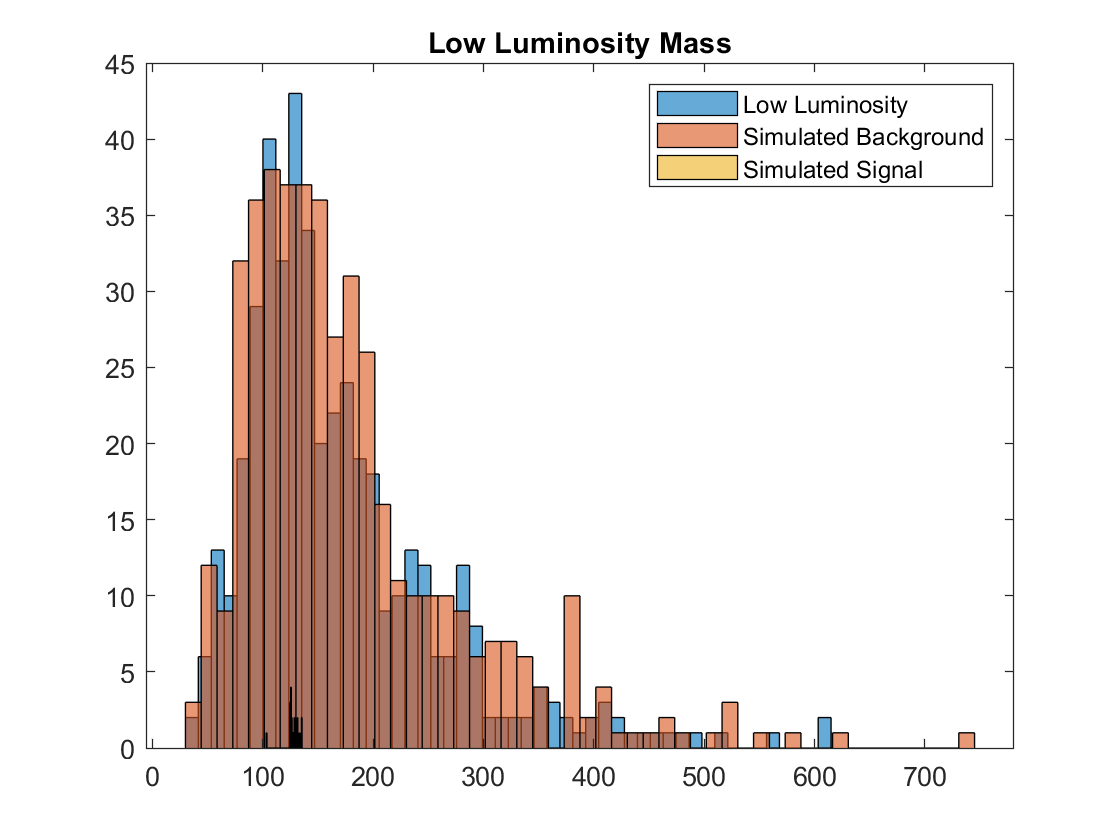


%h5disp("higgs_100000_pt_250_500.h5");
%h5disp("qcd_100000_pt_250_500.h5");

%sig_data = h5read("higgs_100000_pt_250_500.h5",'/higgs_100000_pt_250_500');
sig_data = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');

%bkgnd_data = h5read("qcd_100000_pt_250_500.h5",'/qcd_100000_pt_250_500');
bkgnd_data = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

low_data = h5read("data_lowLumi_pt_1000_1200.h5",'/data/block0_values');

high_data = h5read("data_highLumi_pt_1000_1200.h5",'/data/block0_values');

simul_bkgnd = bkgnd_data(:,1:1+length(high_data(1,:)));

simul_sig = sig_data(:,1:1+length(high_data(1,:)));



histogram(low_data(4,:),50)
title('Low Luminosity Mass')
hold on
histogram(simul_bkgnd(4,1:450),50)
histogram(simul_sig(4,1:22),50)
legend('Low Luminosity','Simulated Background', 'Simulated Signal')
hold off

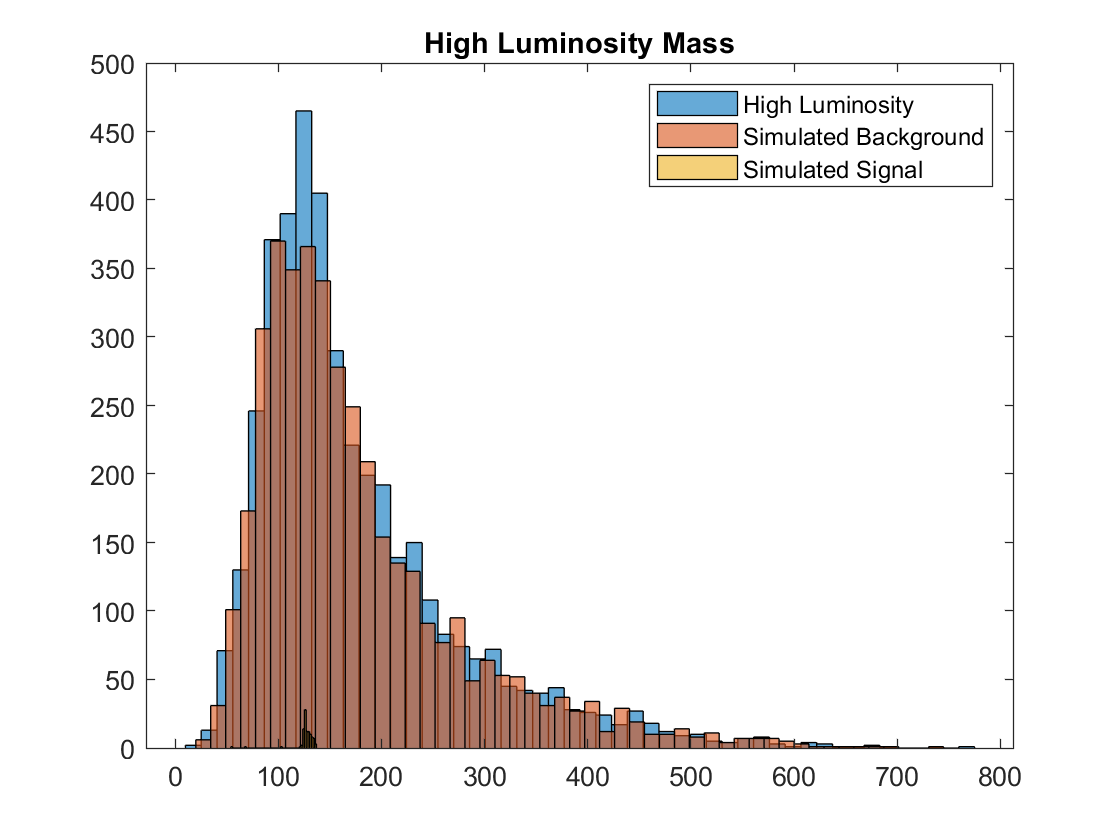

simul_bkgnd_low = simul_bkgnd(:,1:450);
%simul_bkgnd_low = simul_sig;
simul_sig_low = simul_sig(:,1:22);
%simul_sig_low = simul_sig;

histogram(high_data(4,:),50)
hold on
title('High Luminosity Mass')
histogram(simul_bkgnd(4,1:4000),50)
histogram(simul_sig(4,1:100),50)
legend('High Luminosity','Simulated Background', 'Simulated Signal')
hold off

simul_bkgnd_high = simul_bkgnd(:,1:4000);
%simul_bkgnd_low = simul_sig;
simul_sig_high = simul_sig(:,1:100);
%simul_sig_low = simul_sig;

step_hig = 0;
step_qcd = 0;

sim_h = length(high_data(4,:));
sim_l = length(low_data(4,:));
mu_l = length(simul_bkgnd_low);
mu_h = length(simul_bkgnd_high);

for i = 1:length(high_data(4,:))
    if high_data(4,i)>127 || high_data(4,i)<125
         high_data(:,i) = NaN*ones(1,14);
         sim_h = sim_h - 1;
    end
end
for i = 1:length(simul_bkgnd_low)
    if simul_bkgnd_low(4,i)>127 || simul_bkgnd_low(4,i)<125
         simul_bkgnd_low(:,i) = NaN*ones(1,14);
         mu_l = mu_l - 1;
    end
end
for i = 1:length(simul_bkgnd_high)
    if simul_bkgnd_high(4,i)>127 || simul_bkgnd_high(4,i)<125
         simul_bkgnd_high(:,i) = NaN*ones(1,14);
         mu_h = mu_h - 1;
    end
end
for i = 1:length(low_data(4,:))
    if low_data(4,i)>127 || low_data(4,i)<125
         low_data(:,i) = NaN*ones(1,14);
         sim_l = sim_l - 1;
    end
end


sig1_l = poissinv(normcdf(5), mu_l) % this is equivalent to Pythons poisson.ppf I believe

sig1_l = 22

sig1_h = poissinv(normcdf(5), mu_h) % this is equivalent to Pythons poisson.ppf I believe

sig1_h = 96


sig2_l = abs(norminv(1-poisscdf(sim_l, mu_l))) % this is equivalent to Pythons norm.ppf I believe

sig2_l = 0.2697

sig2_h = abs(norminv(1-poisscdf(sim_h, mu_h))) % this is equivalent to Pythons norm.ppf I believe

sig2_h = 5.6222

After doing a mass cut between 125 and 127 we get a significance of 0.2697 on the low luminosity data and 5.6222 on the high luminosiy data. Since the high luminosity data is above the 5 sigma threshold we could stop here and say we have found a signal but we will do additional cuts on the T2 data anyway.

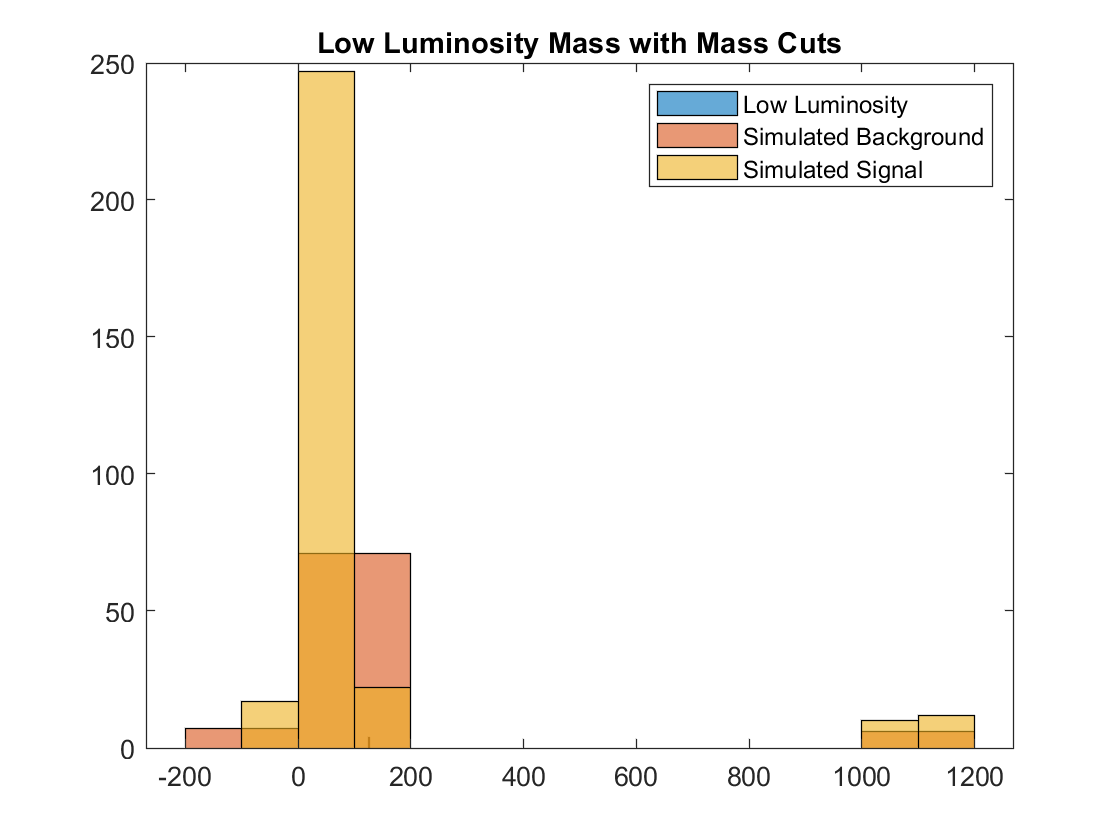

histogram(low_data(4,:))
title('Low Luminosity Mass with Mass Cuts')
hold on
histogram(simul_bkgnd_low)
histogram(simul_sig_low)
legend('Low Luminosity','Simulated Background', 'Simulated Signal')
hold off

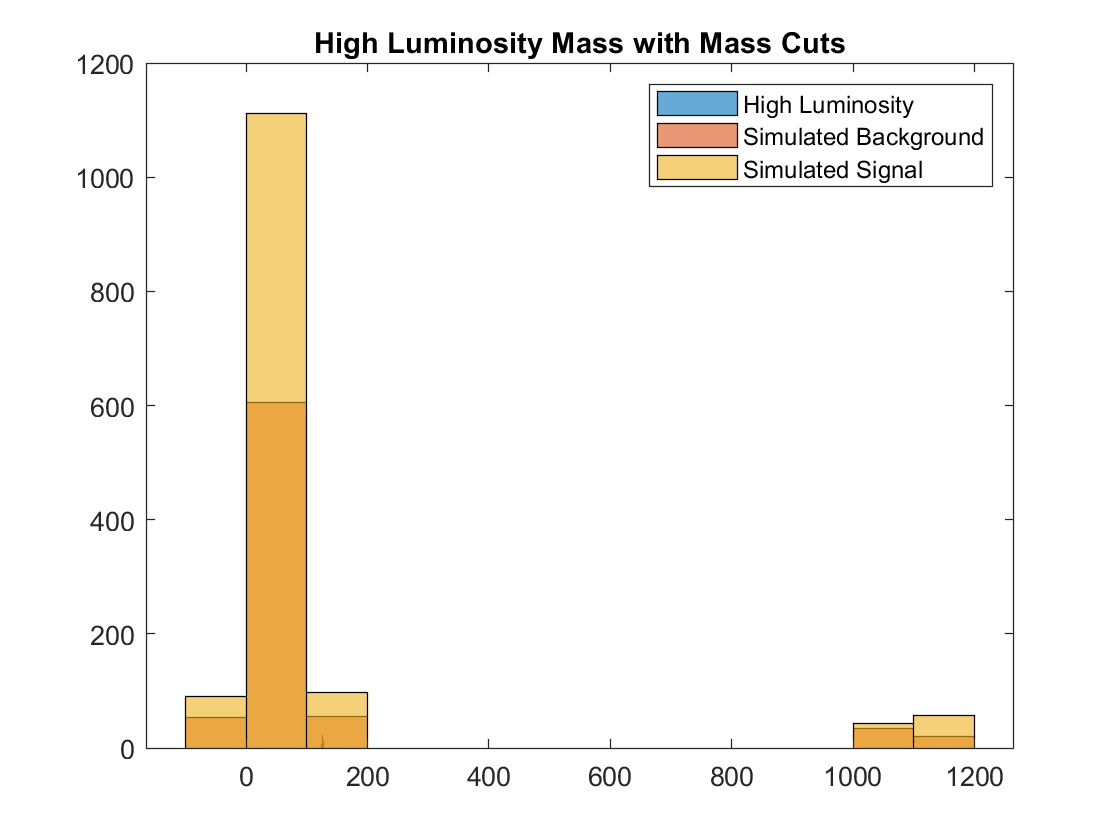


histogram(high_data(4,:))
hold on
title('High Luminosity Mass with Mass Cuts')
histogram(simul_bkgnd_high)
histogram(simul_sig_high)
legend('High Luminosity','Simulated Background', 'Simulated Signal')
hold off

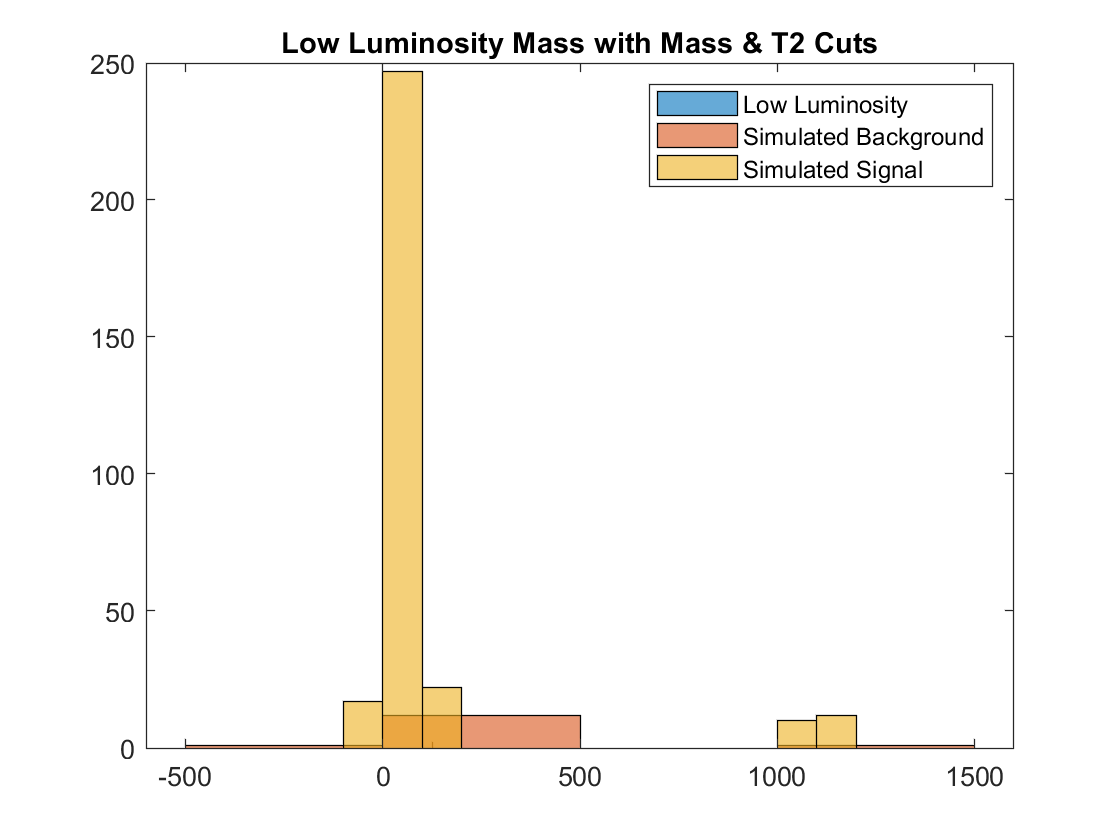





for i = 1:length(high_data(10,:))
    if high_data(10,i)>0.6 || high_data(10,i)<0
         high_data(:,i) = NaN*ones(1,14);
         sim_h = sim_h - 1;
    end
end
for i = 1:length(low_data(10,:))
    if low_data(10,i)>0.6 || low_data(10,i)<0
         low_data(:,i) = NaN*ones(1,14);
         sim_l = sim_l - 1;
    end
end
for i = 1:length(simul_bkgnd_low)
    if simul_bkgnd_low(10,i)>0.6 || simul_bkgnd_low(10,i)<0
         simul_bkgnd_low(:,i) = NaN*ones(1,14);
         mu_l = mu_l - 1;
    end
end
for i = 1:length(simul_bkgnd_high)
    if simul_bkgnd_high(10,i)>0.6 || simul_bkgnd_high(10,i)<0
         simul_bkgnd_high(:,i) = NaN*ones(1,14);
         mu_h = mu_h - 1;
    end
end

histogram(low_data(4,:))
title('Low Luminosity Mass with Mass & T2 Cuts')
hold on
histogram(simul_bkgnd_low)
histogram(simul_sig_low)
legend('Low Luminosity','Simulated Background', 'Simulated Signal')
hold off

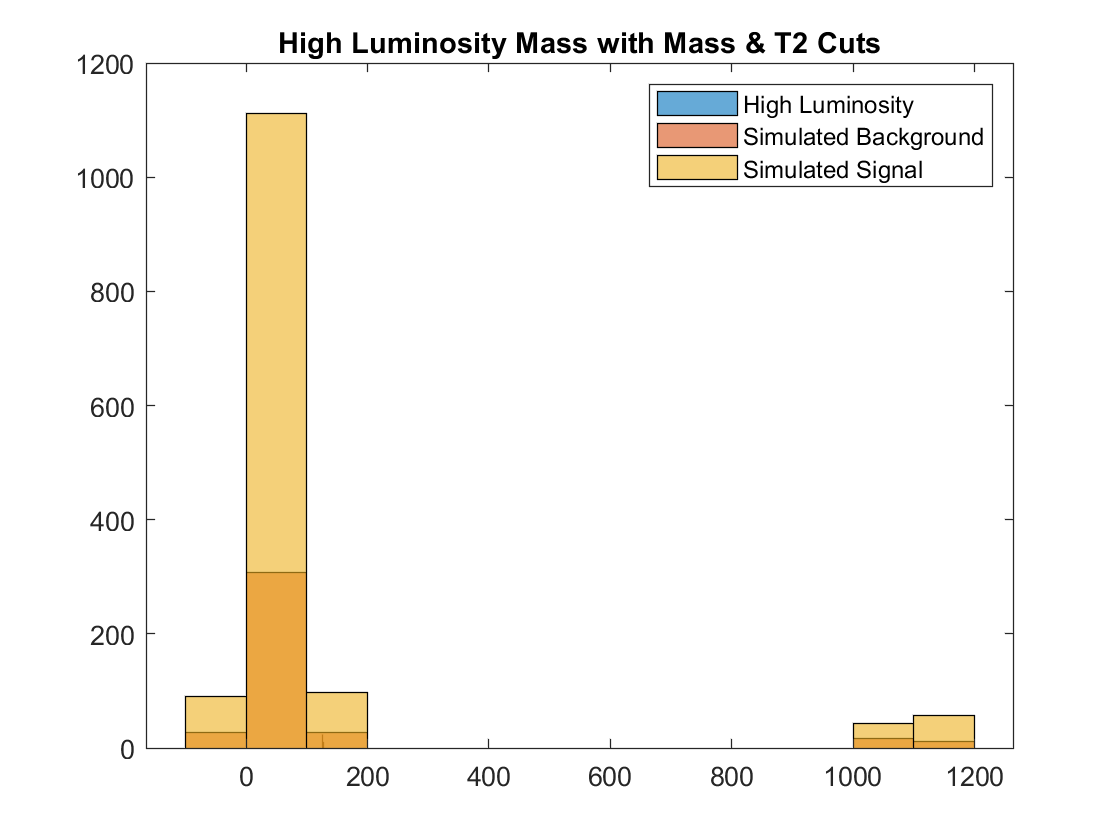


histogram(high_data(4,:))
hold on
title('High Luminosity Mass with Mass & T2 Cuts')
histogram(simul_bkgnd_high)
histogram(simul_sig_high)
legend('High Luminosity','Simulated Background', 'Simulated Signal')
hold off


sig1_l = poissinv(normcdf(5), mu_l) % this is equivalent to Pythons poisson.ppf I believe

sig1_l = 9

sig1_h = poissinv(normcdf(5), mu_h) % this is equivalent to Pythons poisson.ppf I believe

sig1_h = 58


sig2_l = abs(norminv(1-poisscdf(sim_l, mu_l))) % this is equivalent to Pythons norm.ppf I believe

sig2_l = 2.6819

sig2_h = abs(norminv(1-poisscdf(sim_h, mu_h))) % this is equivalent to Pythons norm.ppf I believe

sig2_h = 6.3346

Now after doing a T2 cut between 0 and 0.6 we were able to get a significance of 2.6819 for the low luminosity data and 6.3346 for the high luminosity data. Even with additional cuts the low luminosity data was still unable to get above the 5 sigma threshold (or even close). 


conf95_obslow = poisscdf(sim_l,1.97)

conf95_obslow = 0.9500

conf95_explow = poisscdf(norm_sig_lab8,0.3552)

conf95_explow = 0.9500

Note that I was able to get the mean values for the poisson by "guess and check" with more time I would've liked to have come up with a better method. 

The mean is 1.97 for the observed data to be above a 95% threshold and 0.3552 for the expected data to be above a 95% threshold. This means that to raise the confidence threshold in the data the number of events would need to be more in the observed data compared to the expected data.